# **Description**

    The purpose of this assignment is to understand and implement low pass and high pass filtering. For this assignment we will be using daily stock data from three companies; Exxon Mobil, Corning, and Johnson & Johnson at closing from Janualy 1, 2018 to December 31, 2018.

# **Method**

## Part 1:

    For part 1 we will plotting the time and frequency domain of  the stock data mentioned above. I will be using the plot, fft, and fft functions to display this.

### Results:

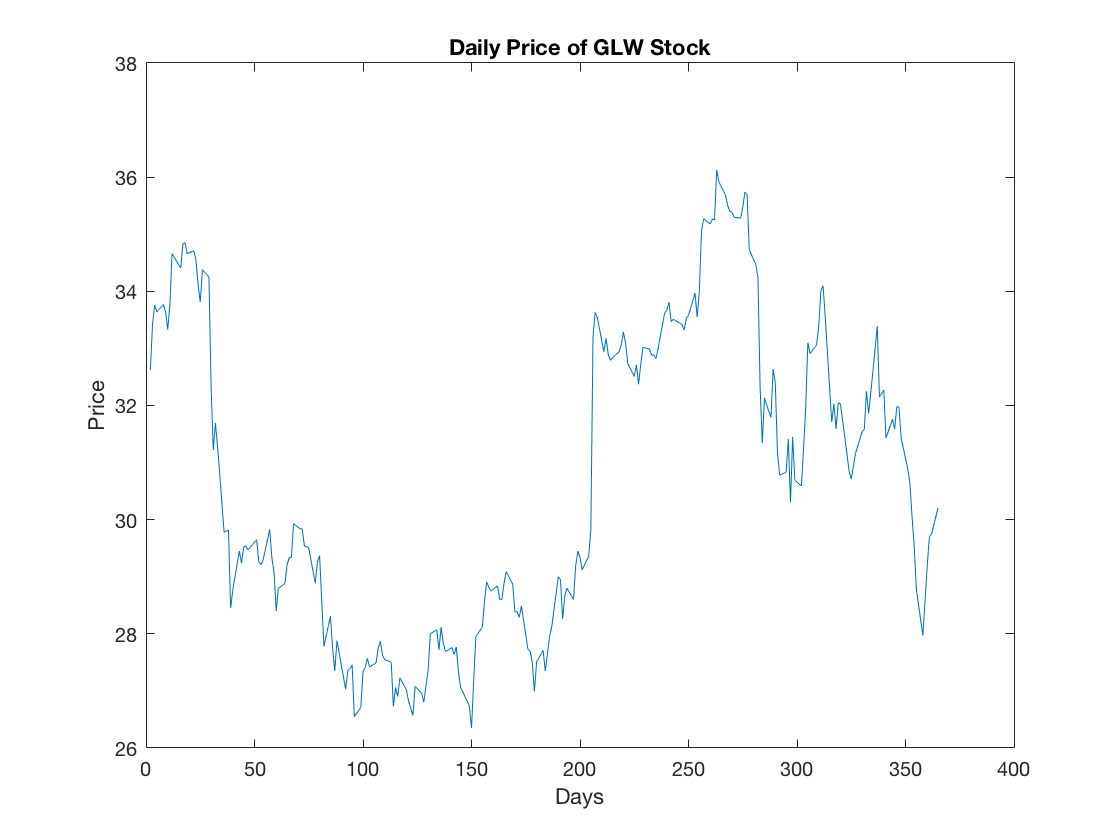

figure; plot(dayofyear,glw);
xlabel('Days'), ylabel('Price')
title('Daily Price of GLW Stock')

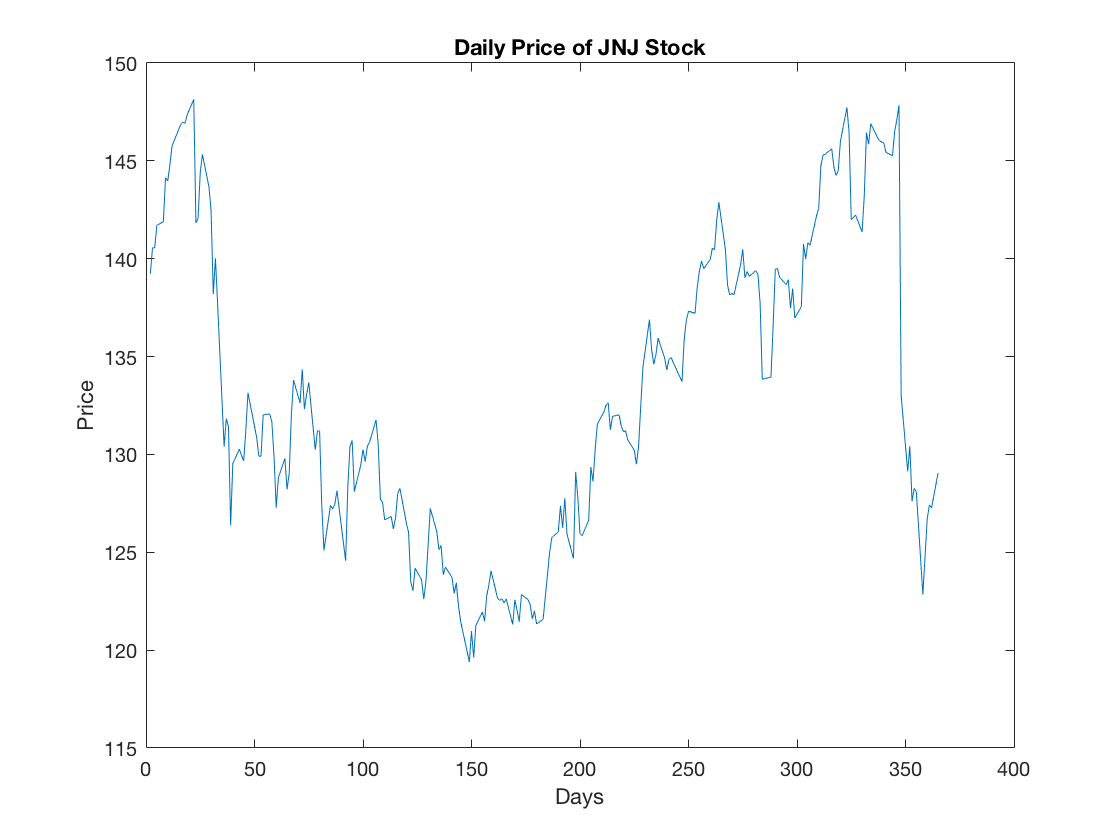

figure; plot(dayofyear,jnj);
xlabel('Days'), ylabel('Price')
title('Daily Price of JNJ Stock')

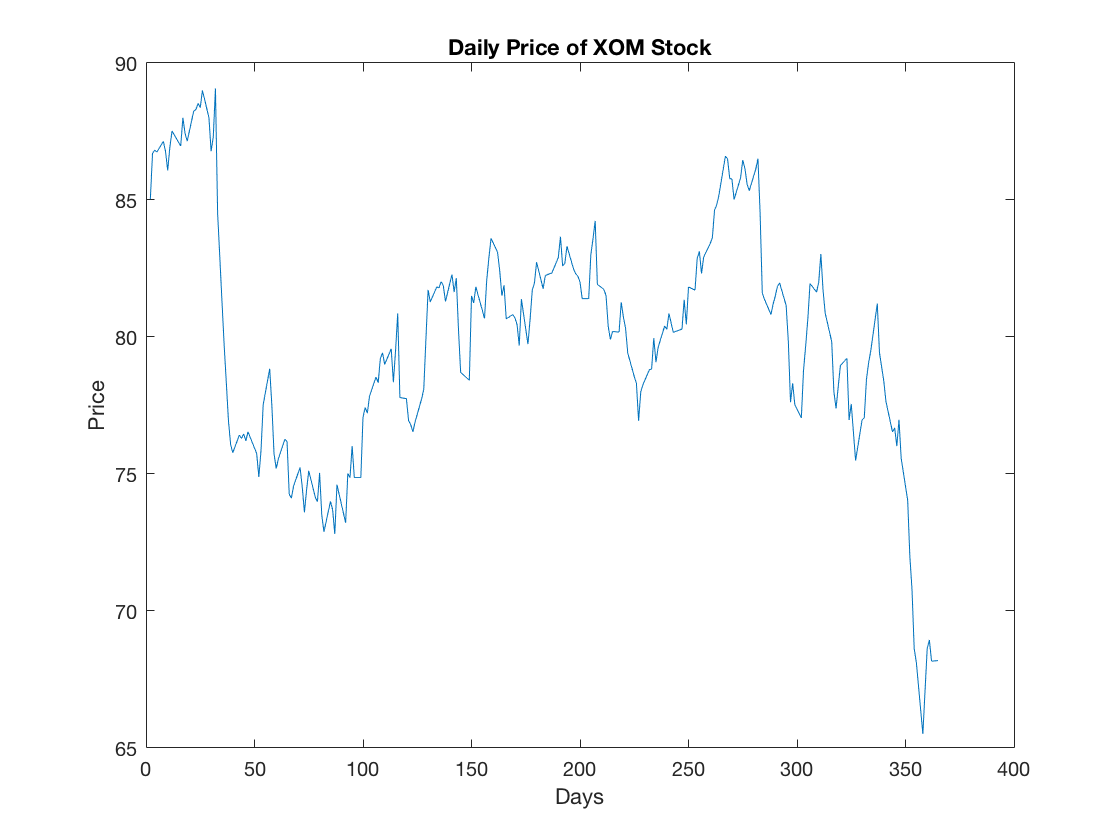

figure; plot(dayofyear,xom)
xlabel('Days'), ylabel('Price')
title('Daily Price of XOM Stock')

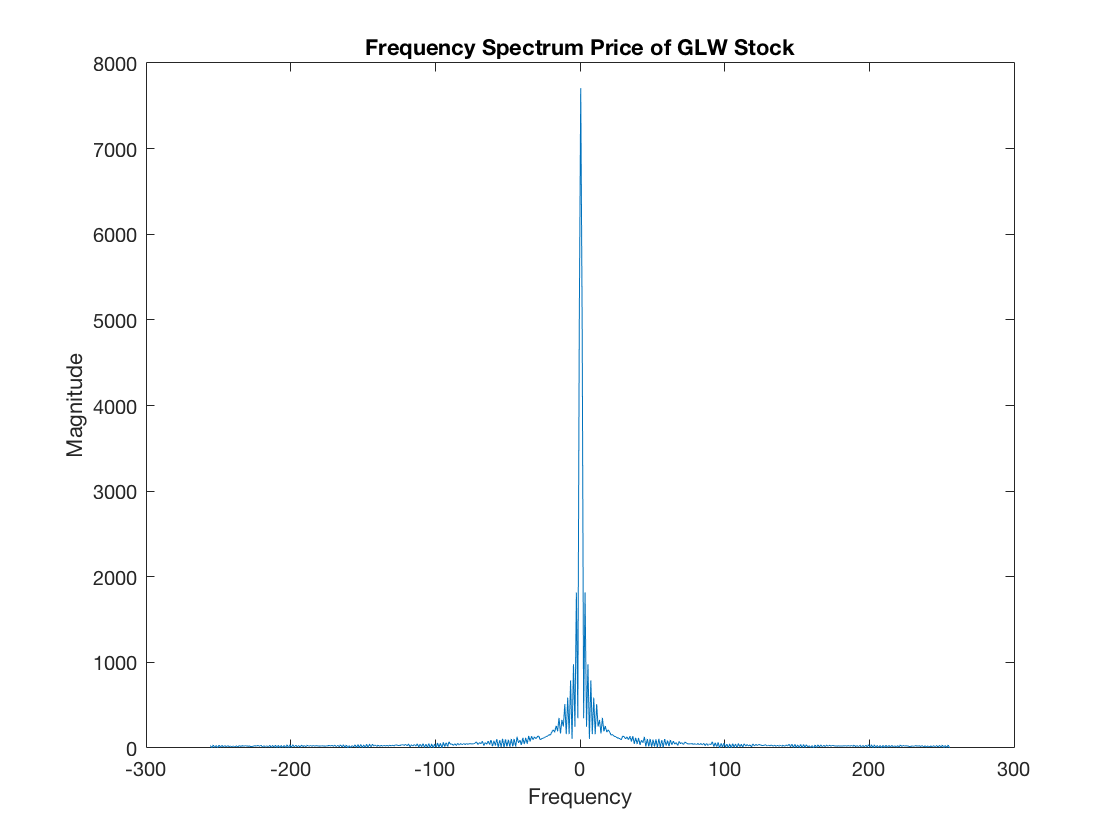

fft_glw = abs(fftshift(fft(glw, 512)));
fft_jnj = abs(fftshift(fft(jnj, 512)));
fft_xom = abs(fftshift(fft(xom, 512)));
f = -511/2:511/2;

figure; plot(f,fft_glw);
xlabel('Frequency'), ylabel('Magnitude')
title('Frequency Spectrum Price of GLW Stock')

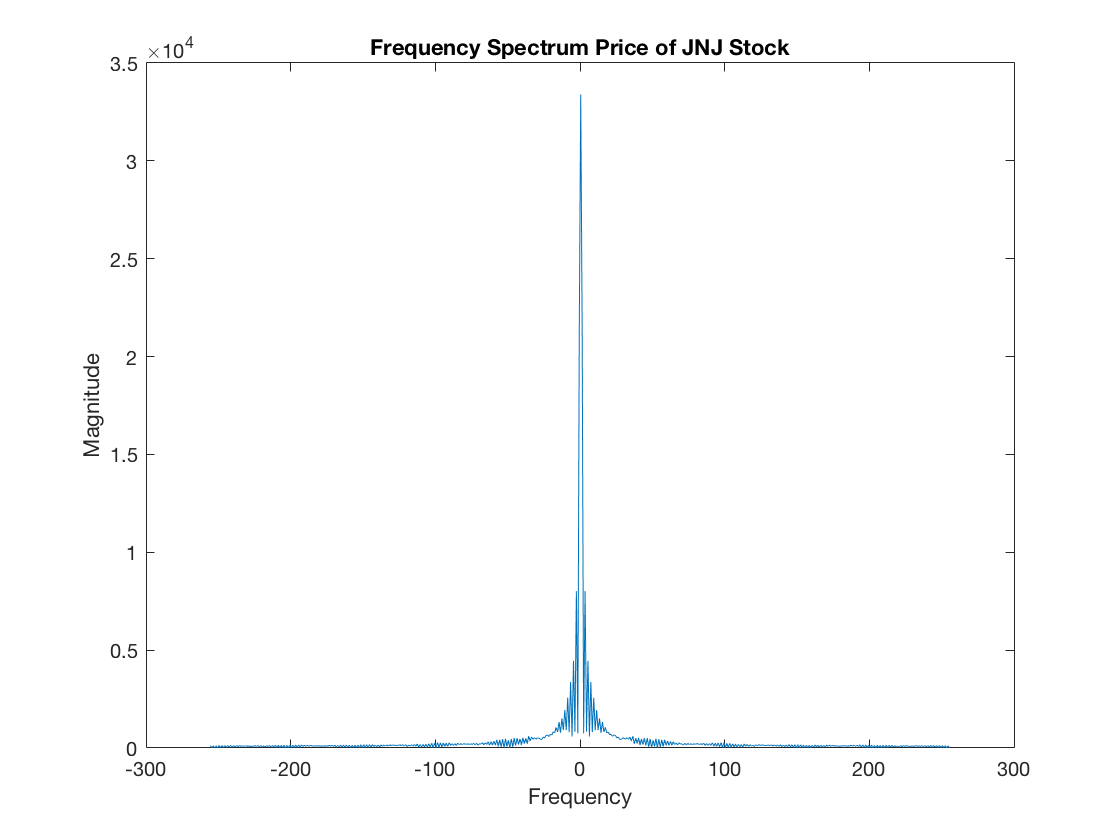

figure; plot(f,fft_jnj);
xlabel('Frequency'), ylabel('Magnitude')
title('Frequency Spectrum Price of JNJ Stock')

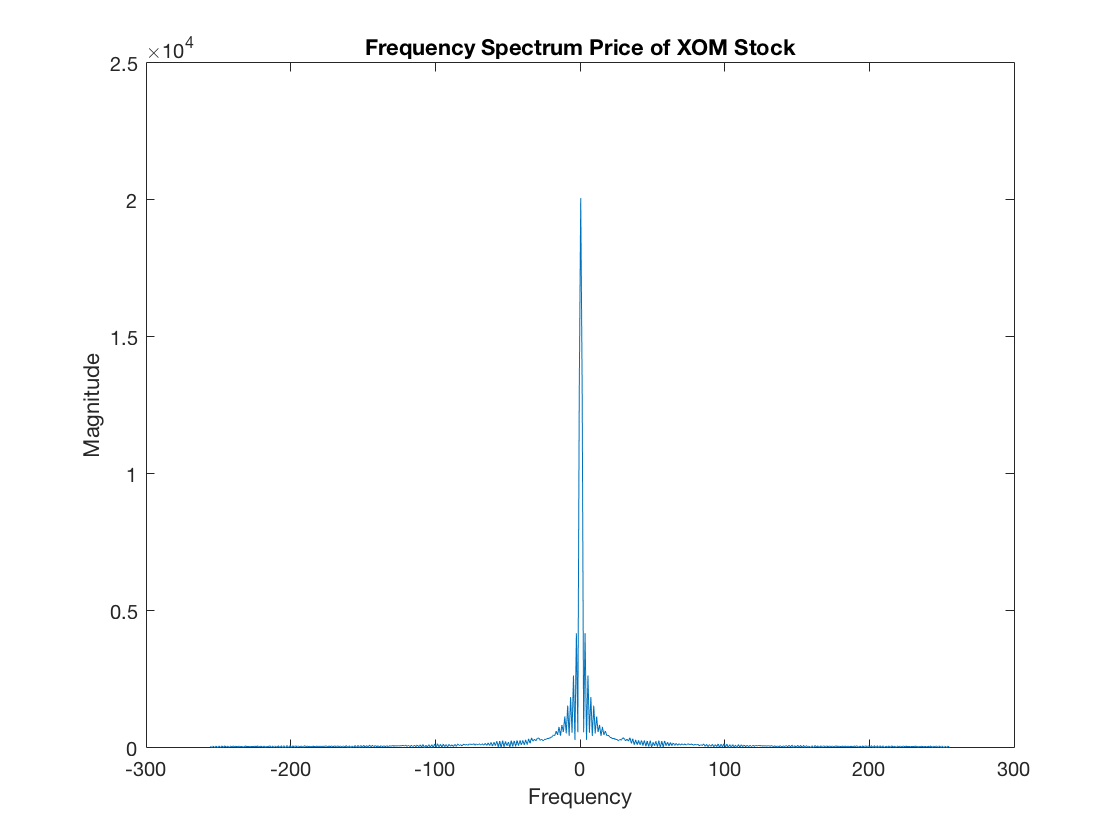

figure; plot(f,fft_xom);
xlabel('Frequency'), ylabel('Magnitude')
title('Frequency Spectrum Price of XOM Stock')

## **Part 2: Low-pass Filtering**

**    A) **Low pass the three sequences with a 5-point moving average filter. I have used the filter function to convolve the kernels with the given data.


$$m_5 \left(n\right)=\left\lbrack x\left(n\right)+x\left(n-1\right)+x\left(n-2\right)+x\left(n-3\right)+x\left(n-4\right)\right\rbrack$$


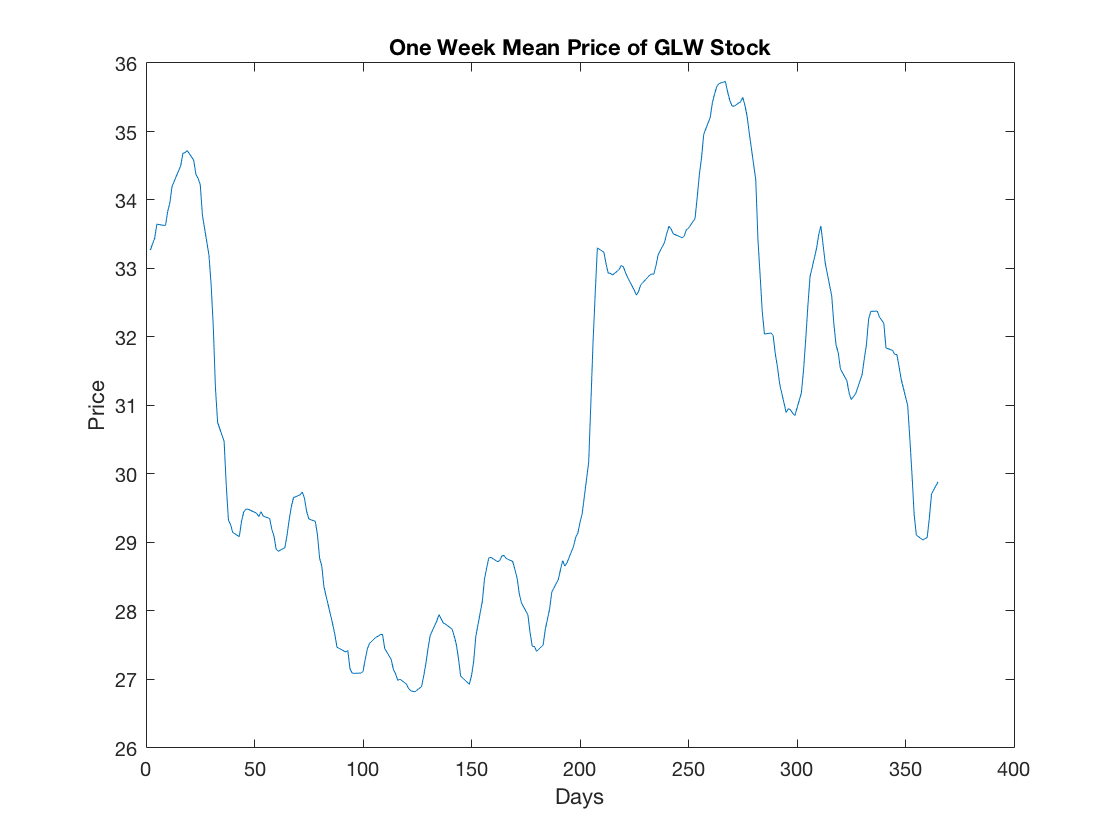

glw_mean = movmean(glw, 5);
jnj_mean = movmean(jnj, 5);
xom_mean = movmean(xom, 5);

figure; plot(dayofyear, glw_mean);
xlabel('Days'), ylabel('Price')
title('One Week Mean Price of GLW Stock')

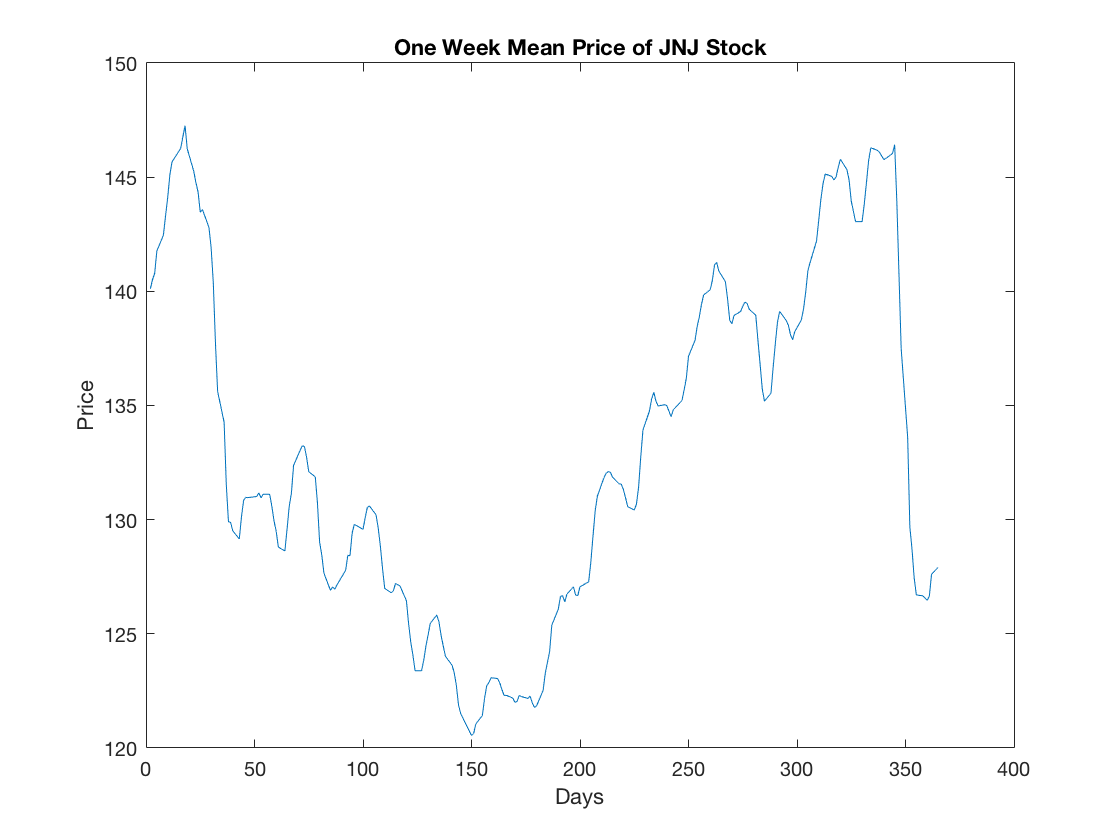

figure; plot(dayofyear,jnj_mean);
xlabel('Days'), ylabel('Price')
title('One Week Mean Price of JNJ Stock')

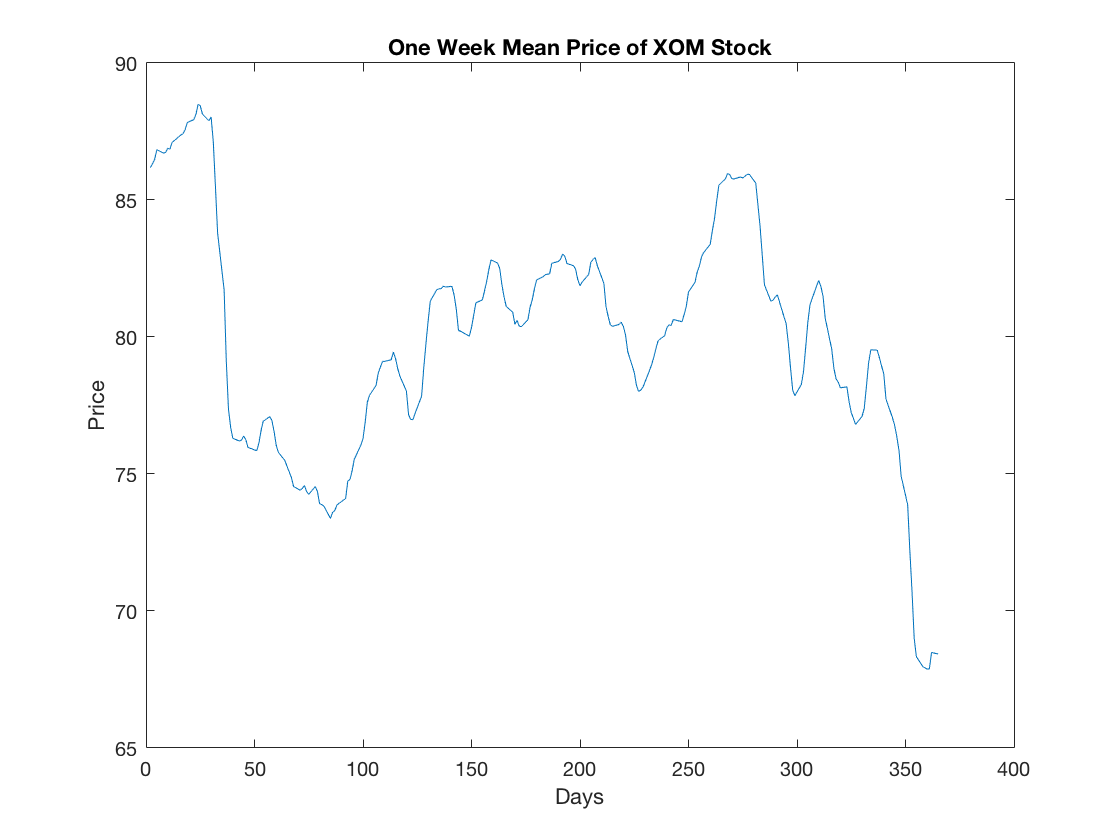


figure; plot(dayofyear, xom_mean);
xlabel('Days'), ylabel('Price')
title('One Week Mean Price of XOM Stock')

    **B) **Observe spectra of low passed sequences.

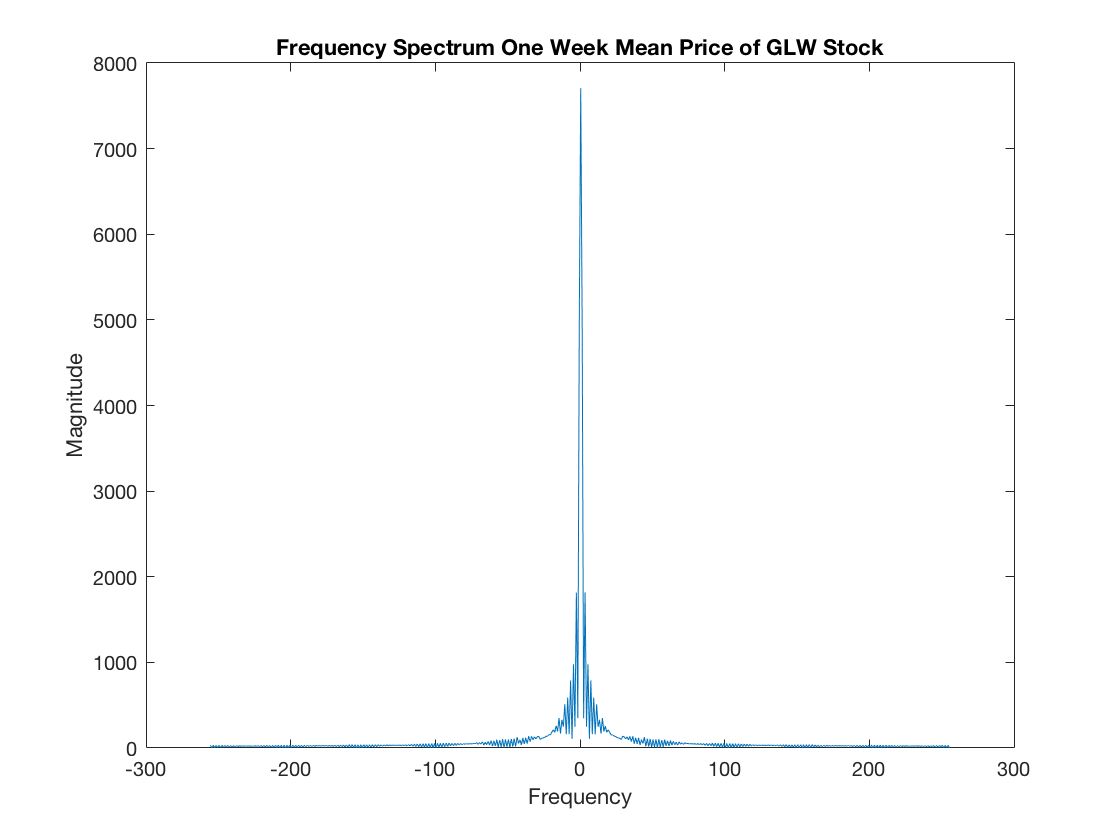

fft_glw = abs(fftshift(fft(glw_mean, 512)));
fft_jnj = abs(fftshift(fft(jnj_mean, 512)));
fft_xom = abs(fftshift(fft(xom_mean, 512)));
f = -511/2:511/2;

figure; plot(f,fft_glw);
xlabel('Frequency'), ylabel('Magnitude')
title('Frequency Spectrum One Week Mean Price of GLW Stock')

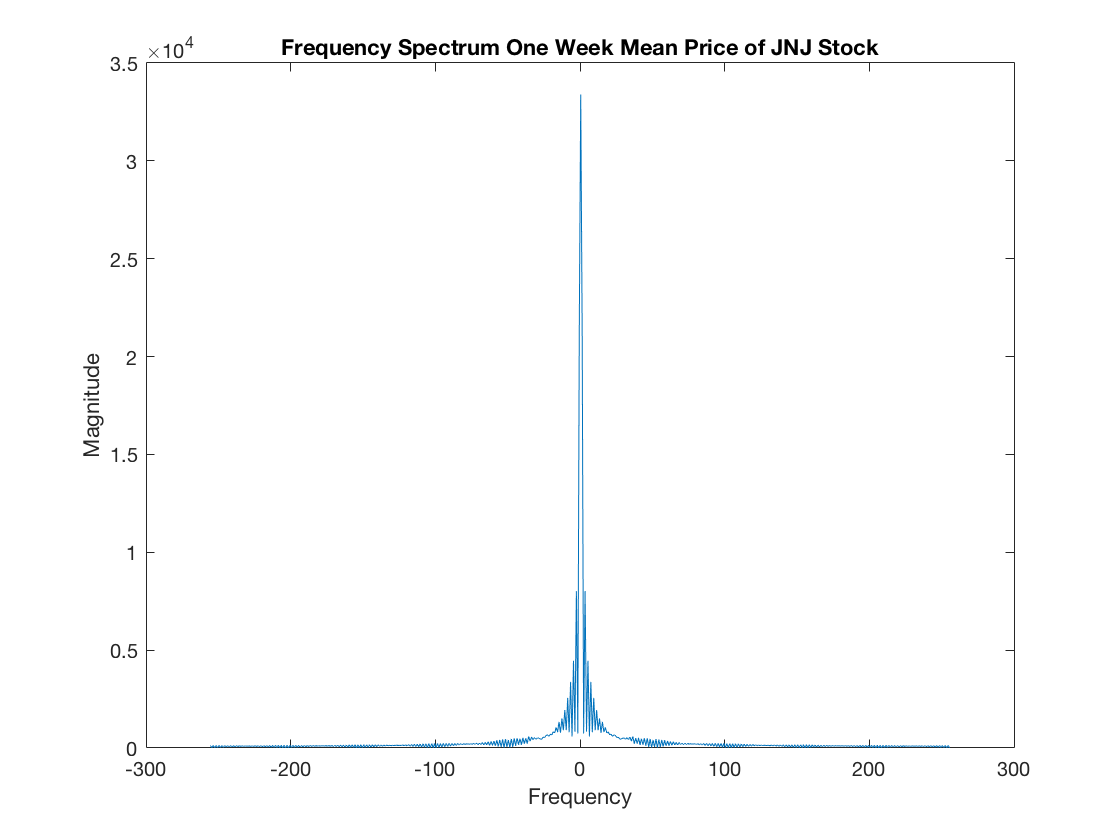

figure; plot(f,fft_jnj);
xlabel('Frequency'), ylabel('Magnitude')
title('Frequency Spectrum One Week Mean Price of JNJ Stock')

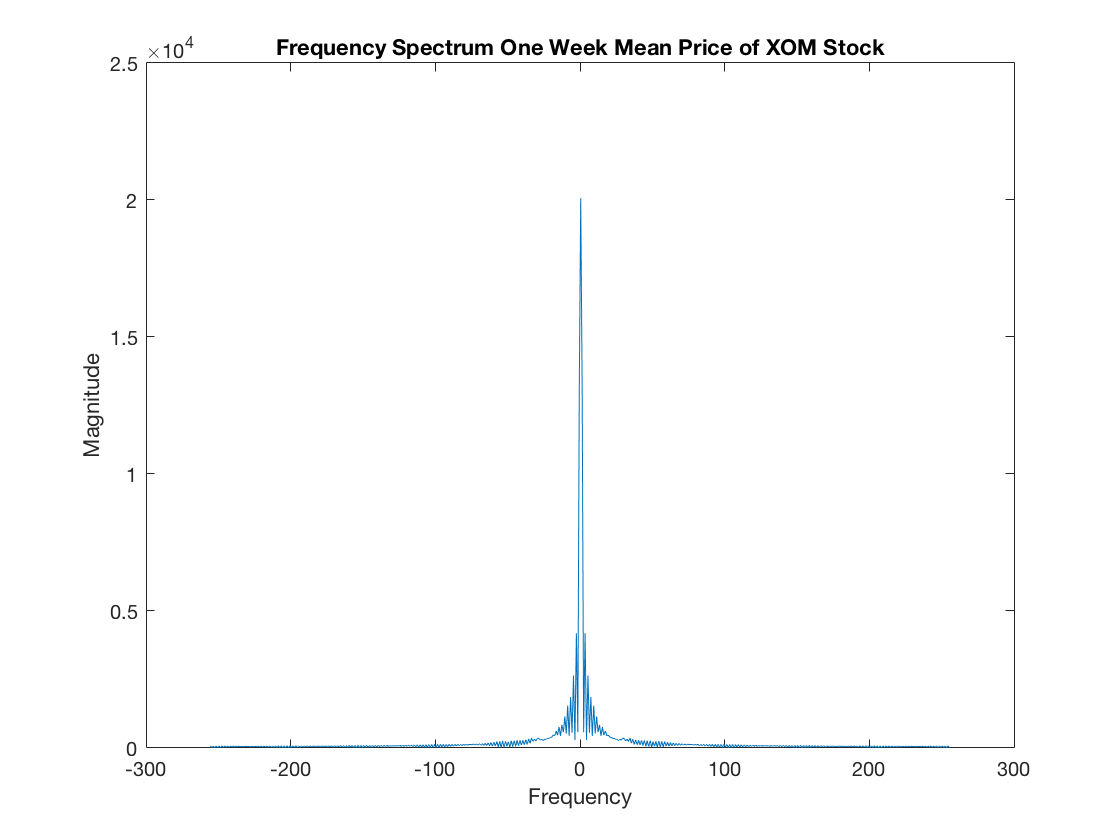

figure; plot(f,fft_xom);
xlabel('Frequency'), ylabel('Magnitude')
title('Frequency Spectrum One Week Mean Price of XOM Stock')

    **C) **Calculate the standard deviation within the observation period and produce boiler bands.

std_glw = std(glw)

std_glw = 2.6746

std_jnj = std(jnj)

std_jnj = 7.7264

std_xom = std(xom)

std_xom = 4.3144

Plots of Bollinger Bands:


$$\begin{array}{l}
B_1 \left(n\right)=m\left(n\right)\pm \sigma \left(n\right)\\
B_2 \left(n\right)=m\left(n\right)\pm 2\sigma \left(n\right)
\end{array}$$


    To calculate the Bollinger Band I used two methods and chose the one that gave me better results. My first method involved using the Filter function to convolve the moving average kernel with the data, but because of zero padding distortion at the edges, the Bollinger band had a significant drop at the begging and overall slight shift to the right. The second method involved using the movmean function which a higher level function that takes care of the edge distortion and gave me better results. No data stepped out of any of the three Bollinger Band plots using a 5 day mean.

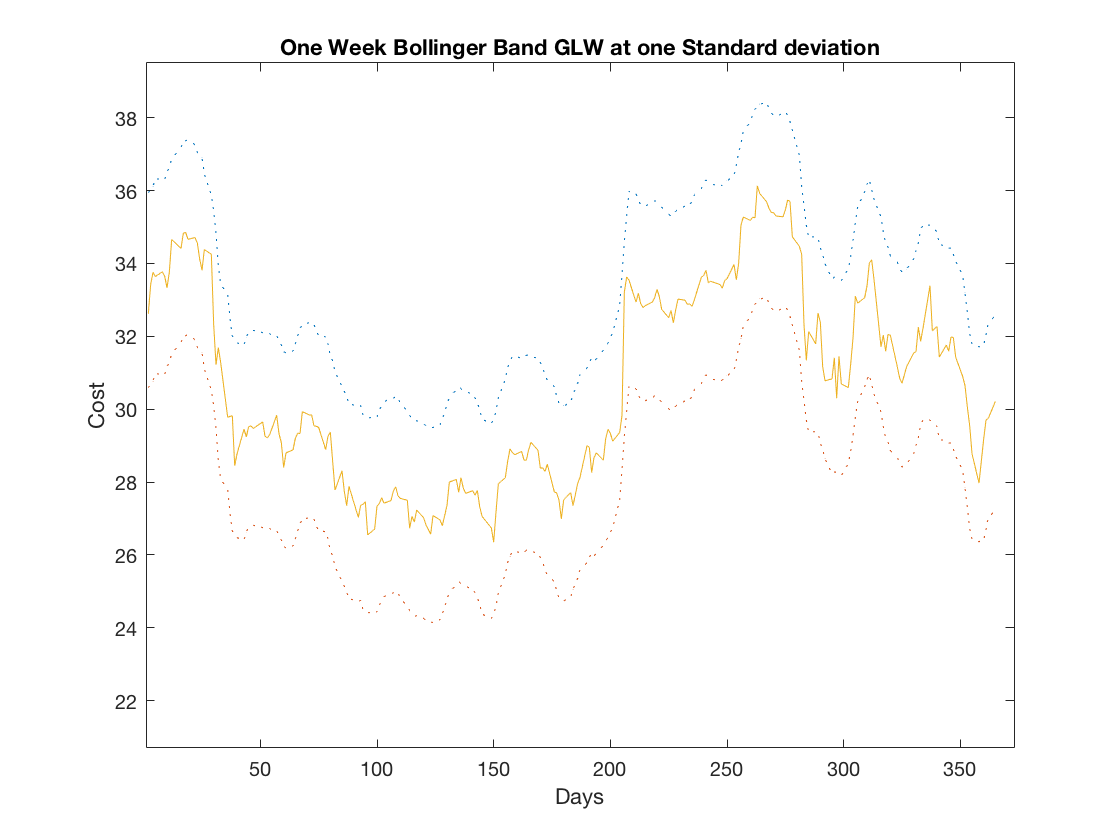

b1n_glw = glw_mean + std_glw;
b1n_glw_n = glw_mean - std_glw;
figure; plot(dayofyear, b1n_glw,":"); hold on
plot(dayofyear, b1n_glw_n,":");
plot(dayofyear, glw)
xlabel('Days'), ylabel('Cost')
title('One Week Bollinger Band GLW at one Standard deviation')
xlim([1 373]); ylim([20.7 39.5])

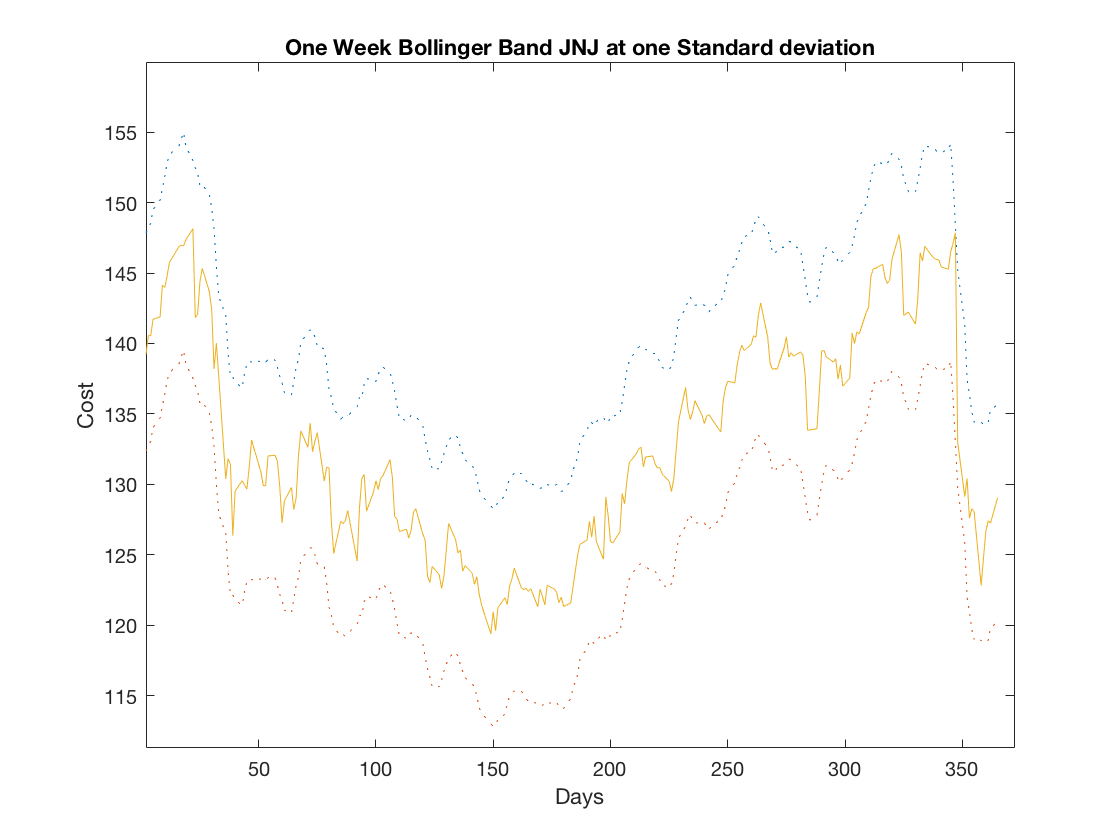

b1n_jnj = jnj_mean + std_jnj;
b1n_jnj_n = jnj_mean - std_jnj;
figure; plot(dayofyear, b1n_jnj,":"); hold on
plot(dayofyear, b1n_jnj_n,":");
plot(dayofyear, jnj)
xlabel('Days'), ylabel('Cost')
title('One Week Bollinger Band JNJ at one Standard deviation')
xlim([2 372]); ylim([111.3 159.9])

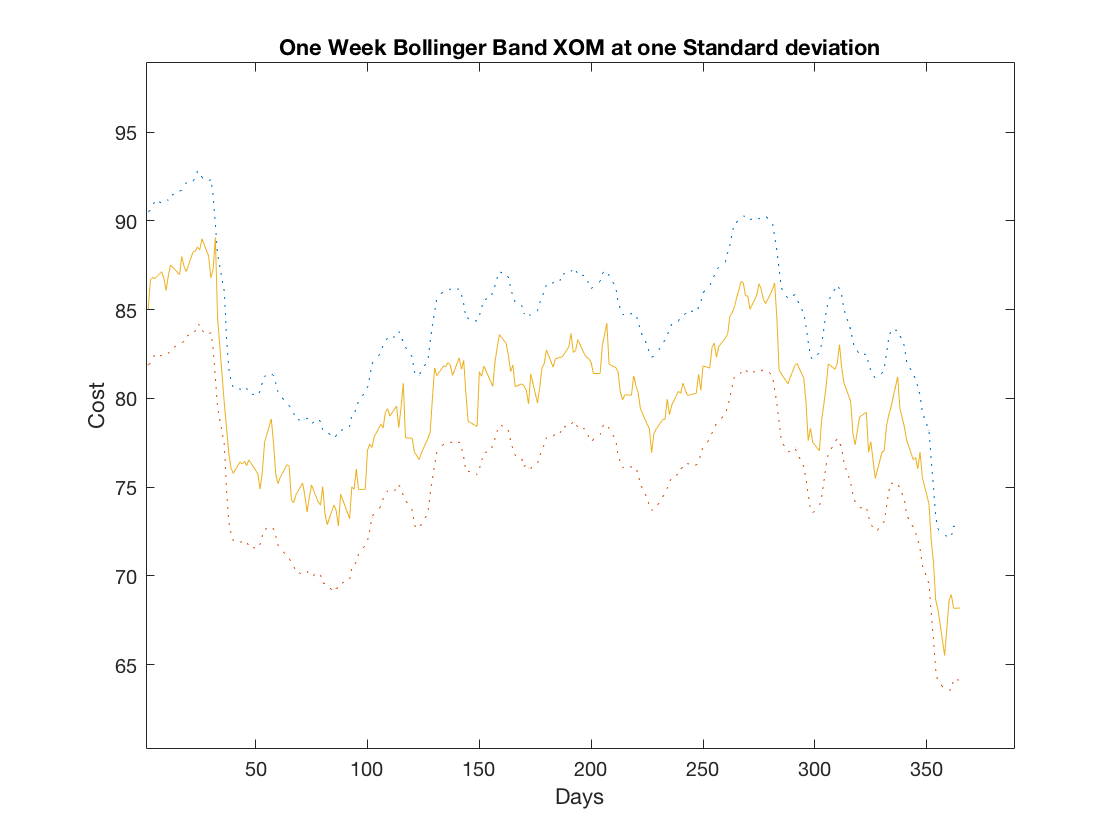

b1n_xom = xom_mean + std_xom;
b1n_xom_n = xom_mean - std_xom;
figure; plot(dayofyear, b1n_xom,":"); hold on
plot(dayofyear, b1n_xom_n,":");
plot(dayofyear, xom)
xlabel('Days'), ylabel('Cost')
title('One Week Bollinger Band XOM at one Standard deviation')
xlim([1 389]); ylim([60.3 98.9])

    **D-E)  **Low pass the three sequences with a 20-point moving average filter. I have used the movmean function to convolve the kernels with the given data.


$$m_{20} \left(n\right)=\frac{1}{20}\left\lbrack x\left(n\right)+x\left(n-1\right)+x\left(n-2\right)+\dots +x\left(n-20+1\right)\right\rbrack$$


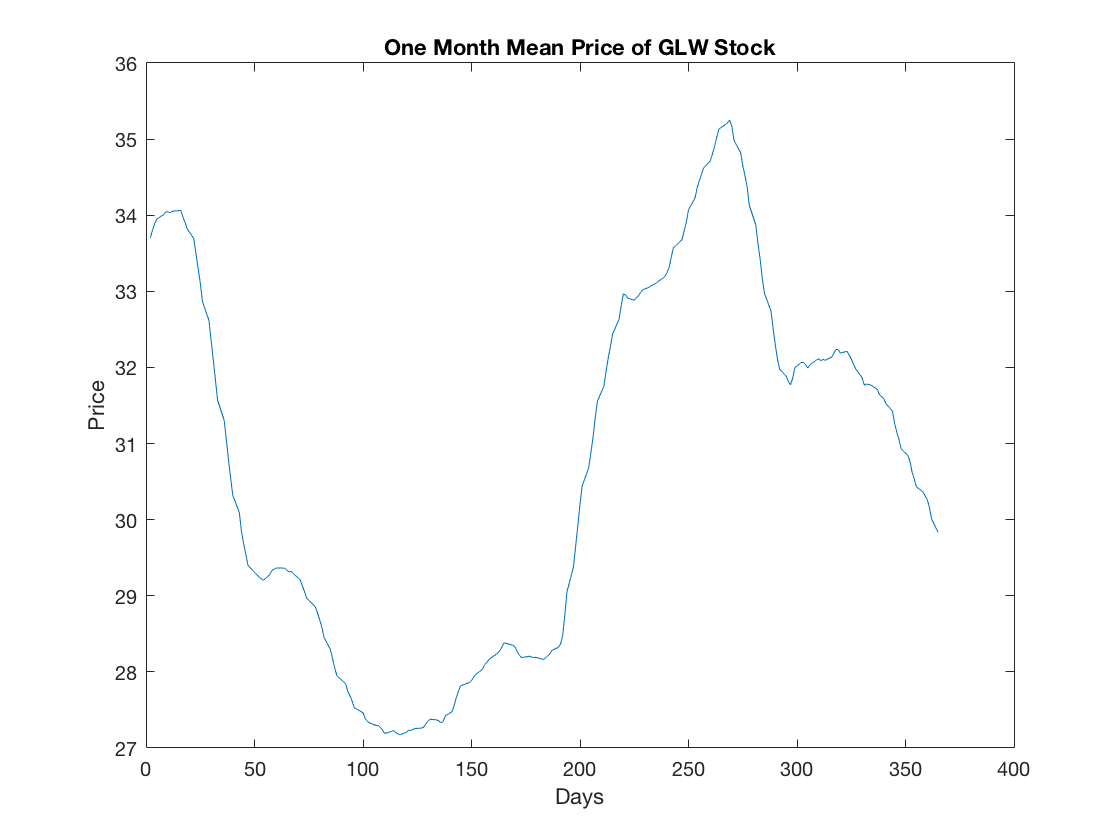

glw_mean = movmean(glw, 20);
jnj_mean = movmean(jnj, 20);
xom_mean = movmean(xom, 20);

figure; plot(dayofyear, glw_mean);
xlabel('Days'), ylabel('Price')
title('One Month Mean Price of GLW Stock')

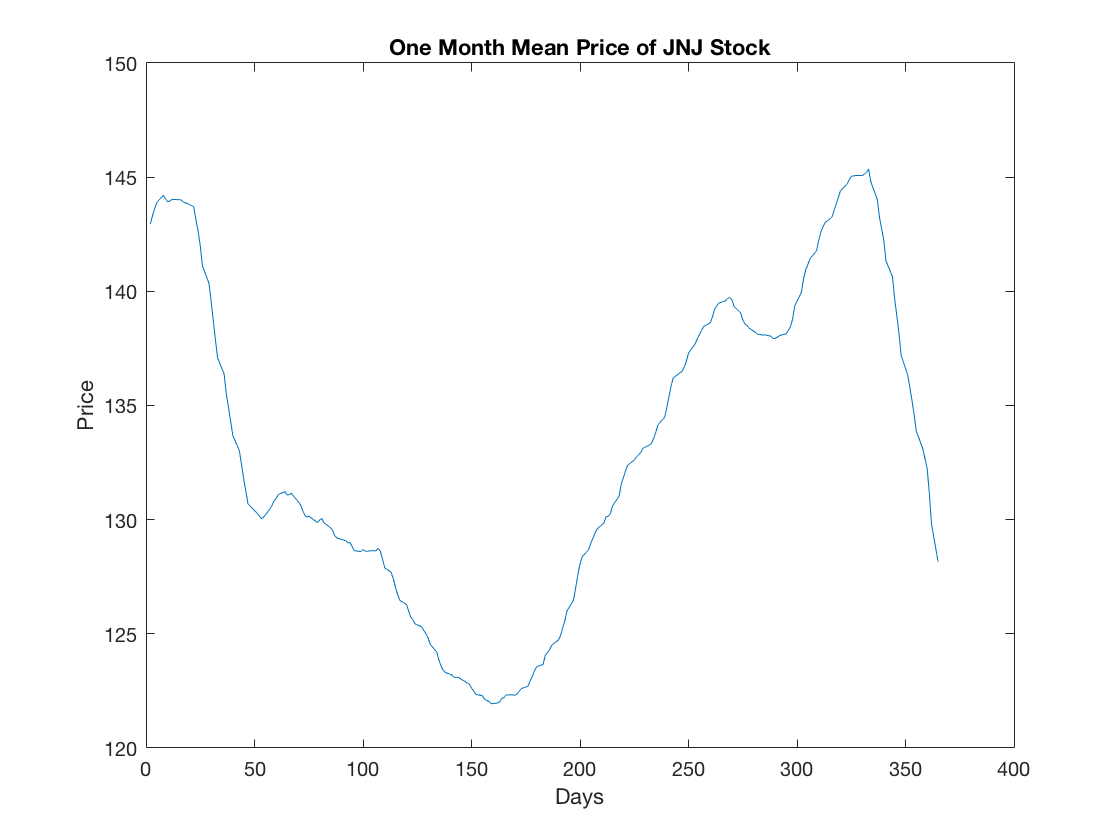

figure; plot(dayofyear,jnj_mean);
xlabel('Days'), ylabel('Price')
title('One Month Mean Price of JNJ Stock')

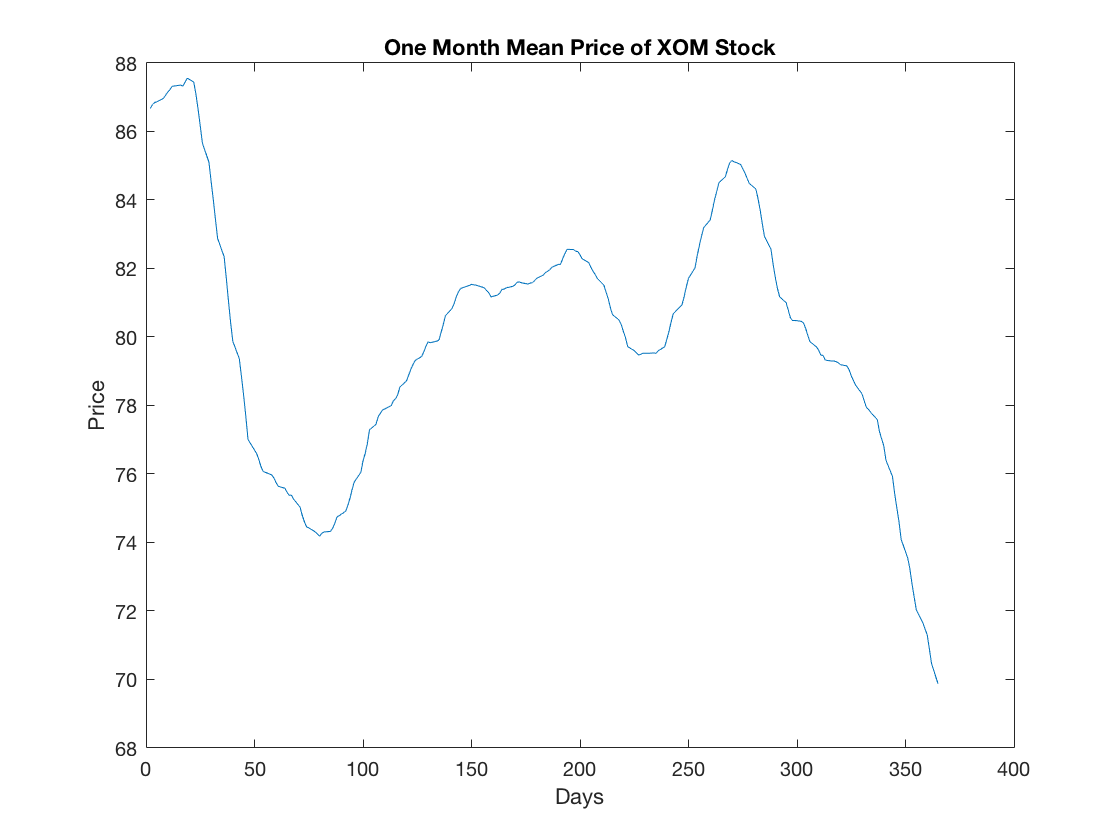

figure; plot(dayofyear, xom_mean);
xlabel('Days'), ylabel('Price')
title('One Month Mean Price of XOM Stock')

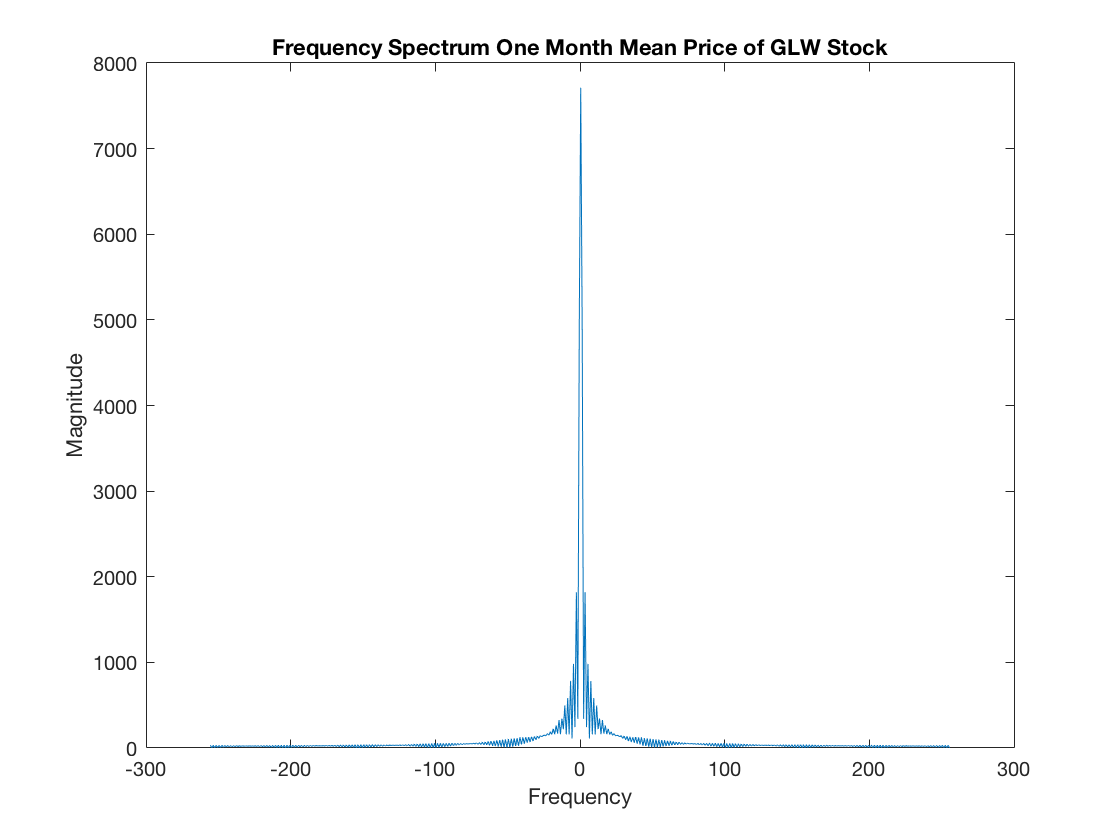

fft_glw = abs(fftshift(fft(glw_mean, 512)));
fft_jnj = abs(fftshift(fft(jnj_mean, 512)));
fft_xom = abs(fftshift(fft(xom_mean, 512)));
f = -511/2:511/2;

figure; plot(f,fft_glw);
xlabel('Frequency'), ylabel('Magnitude')
title('Frequency Spectrum One Month Mean Price of GLW Stock')

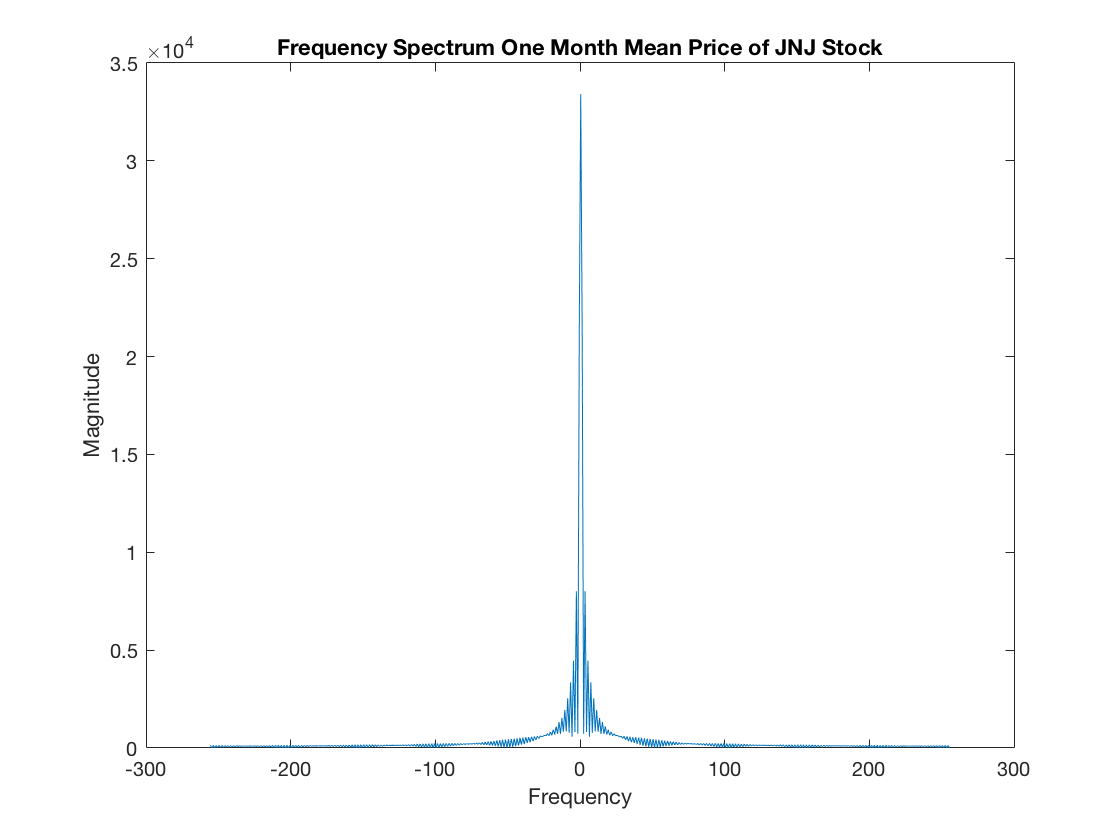

figure; plot(f,fft_jnj);
xlabel('Frequency'), ylabel('Magnitude')
title('Frequency Spectrum One Month Mean Price of JNJ Stock')

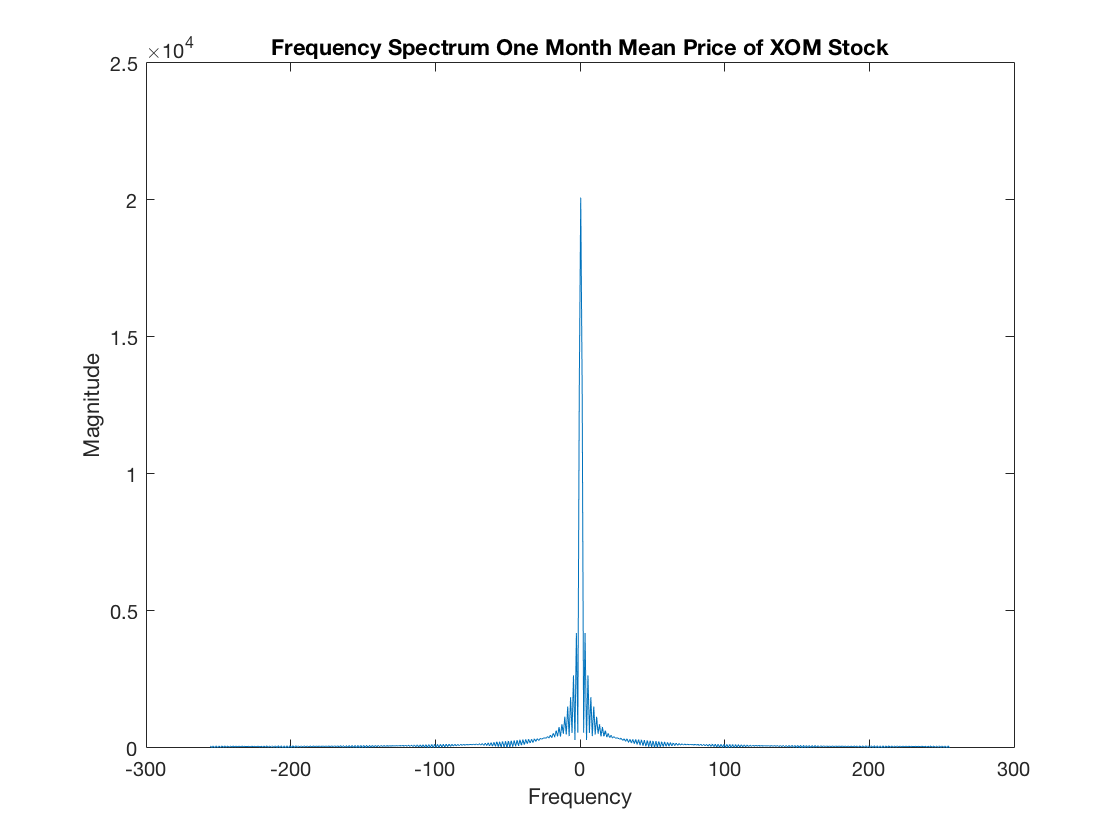

figure; plot(f,fft_xom);
xlabel('Frequency'), ylabel('Magnitude')
title('Frequency Spectrum One Month Mean Price of XOM Stock')

std_glw = std(glw)

std_glw = 2.6746

std_jnj = std(jnj)

std_jnj = 7.7264

std_xom = std(xom)

std_xom = 4.3144

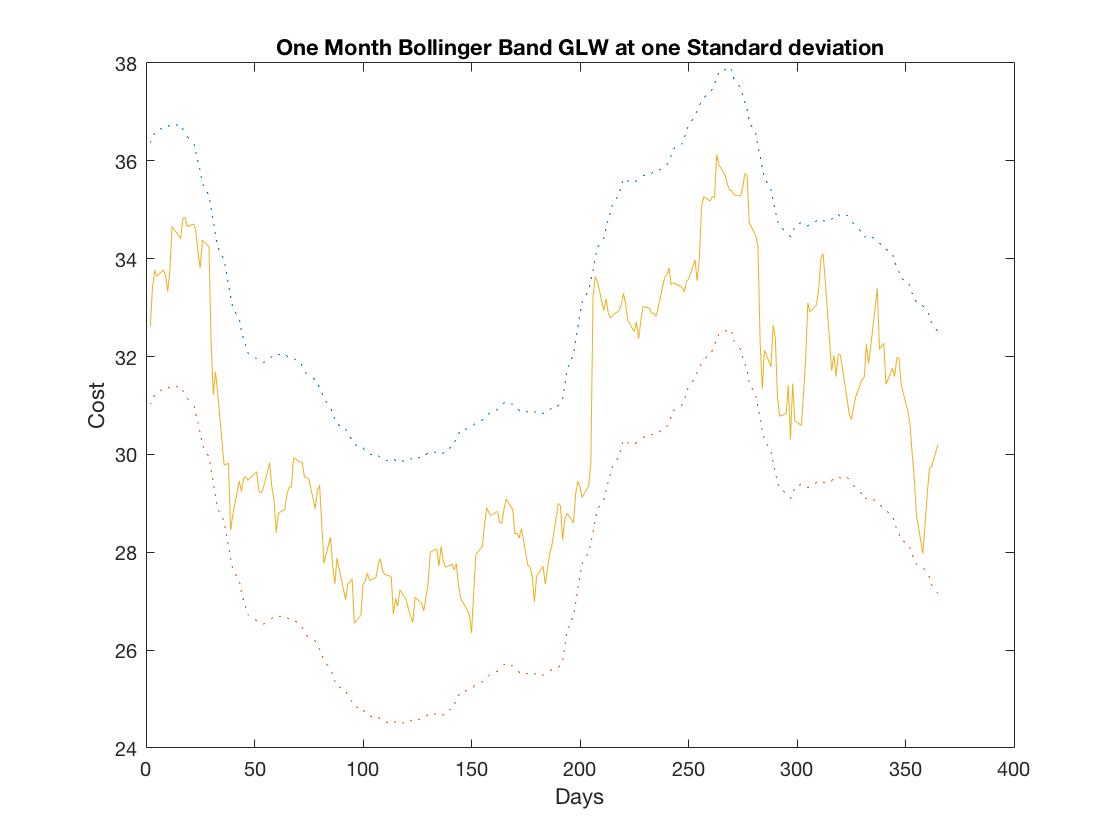

b1n_glw = glw_mean + std_glw;
b1n_glw_n = glw_mean - std_glw;
figure; plot(dayofyear, b1n_glw,":"); hold on
plot(dayofyear, b1n_glw_n,":");
plot(dayofyear, glw)
xlabel('Days'), ylabel('Cost')
title('One Month Bollinger Band GLW at one Standard deviation')

GLW stock did not over step the one month Bollinger Band at one standar deviation.

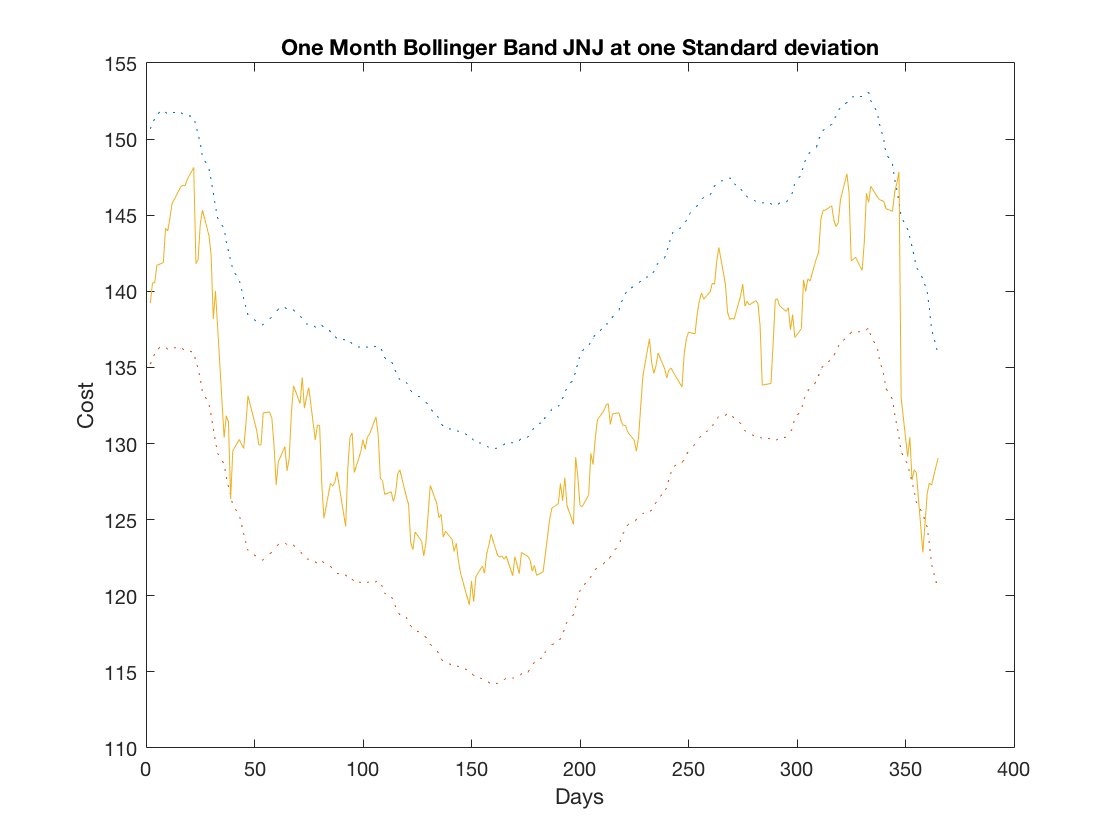

b1n_jnj = jnj_mean + std_jnj;
b1n_jnj_n = jnj_mean - std_jnj;
figure; plot(dayofyear, b1n_jnj,":"); hold on
plot(dayofyear, b1n_jnj_n,":");
plot(dayofyear, jnj)
xlabel('Days'), ylabel('Cost')
title('One Month Bollinger Band JNJ at one Standard deviation')

For JNJ, the stock stepped out of the Bollinger bands for days 39, 347, and 358 for the one month Bollinger Band plot at one standard deviation.

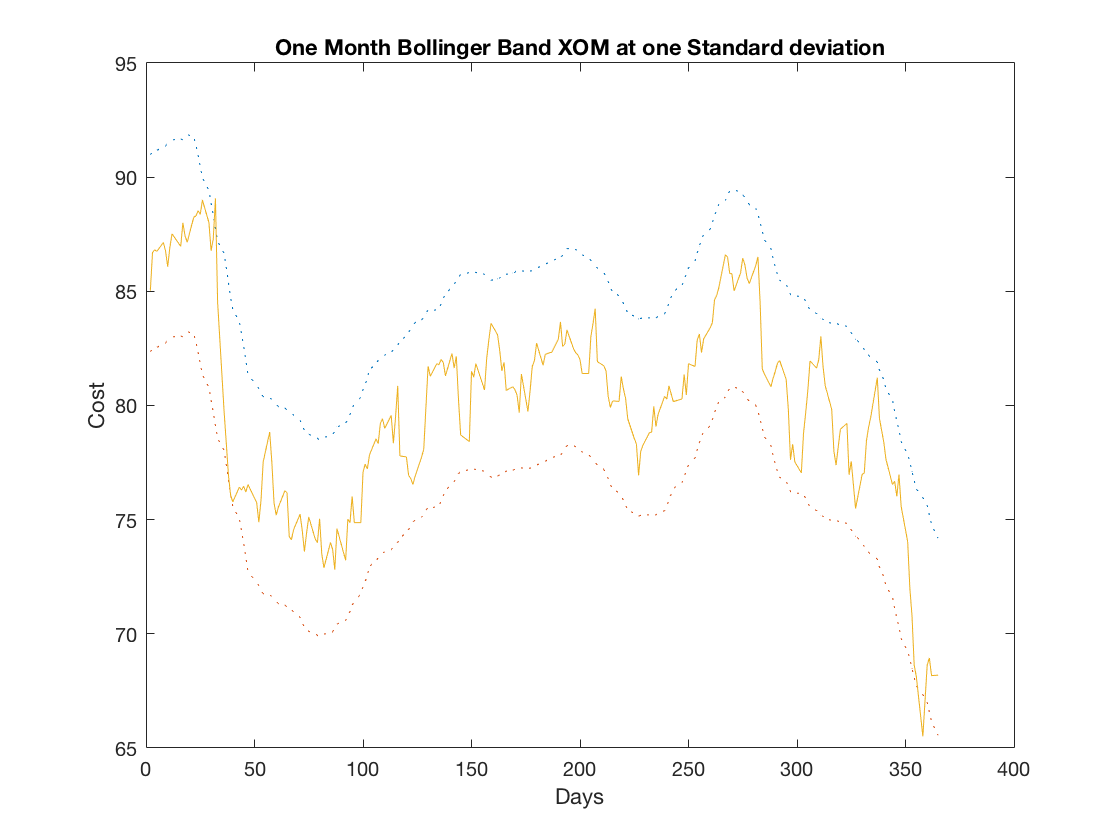

b1n_xom = xom_mean + std_xom;
b1n_xom_n = xom_mean - std_xom;
figure; plot(dayofyear, b1n_xom,":"); hold on
plot(dayofyear, b1n_xom_n, ":");
plot(dayofyear, xom)
xlabel('Days'), ylabel('Cost')
title('One Month Bollinger Band XOM at one Standard deviation')

For XOM, the stock stepped out of the Bollinger bands for days 32 and 358 for the one month Bollinger Band plot at one standard deviation.

**F) **I have been able to show that for the one week mean calculations, none of three stock had anomalies where the stock deviated above or below the Bollinger Bands. On the other hand, the one month mean calculations show a few anomalies in the stock during the year. GLW did not have anomalies throught the year, JNJ had anomalies in days 39, 347, and 358, while XOM had anomalies in days 32 and 358. It's safe to conclude based on the plots, that day 32 was the best day to sell XOM stock, while day 358 was the best day to buy. Furthermore, JNJ's best day to sell stock was day 347 and the best day to buy stock was day 358.

## Part 3: Change Detection (**highpass filtering, 1st-order)**

**    A) **Apply 2 point change detection filter to the 3 stock sequences illustrated in part 1.

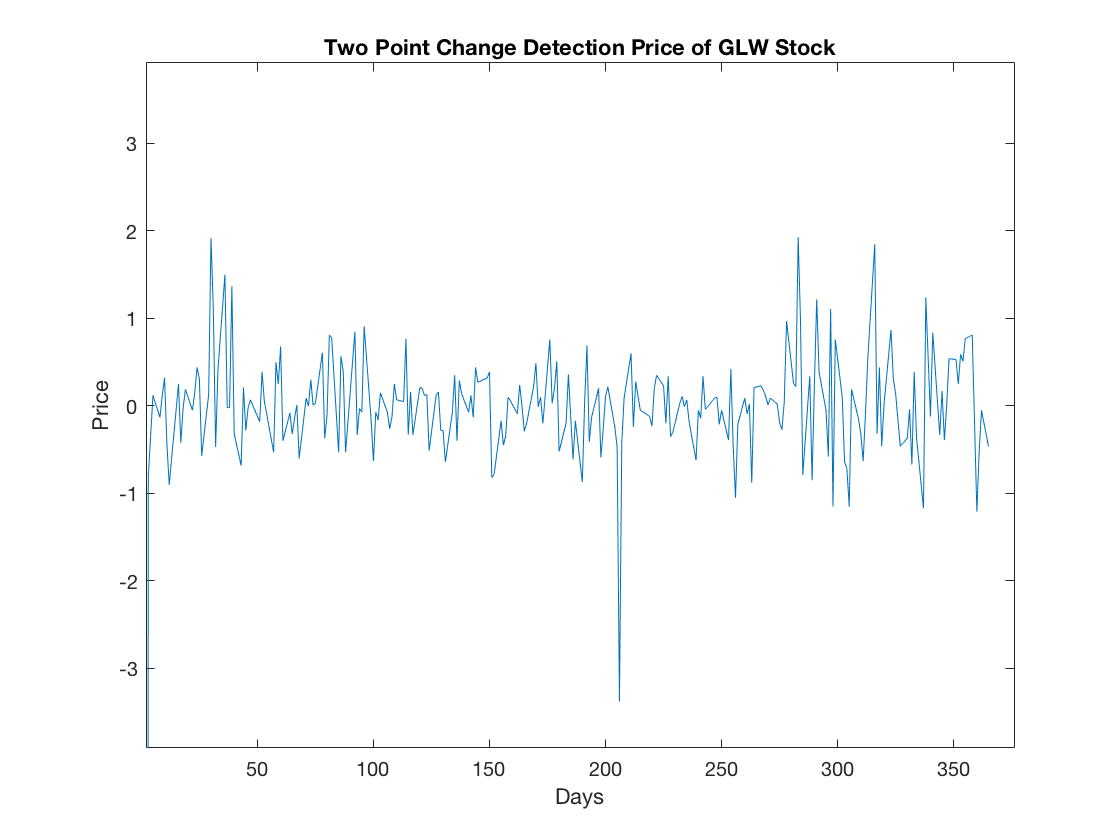

two_point_change_detection = [-1, 1];
glw_high_passed = filter(two_point_change_detection, 1, glw);
figure; plot(dayofyear, glw_high_passed);
xlabel('Days'), ylabel('Price')
title('Two Point Change Detection Price of GLW Stock')
xlim([2 376]);ylim([-3.91 3.92]);

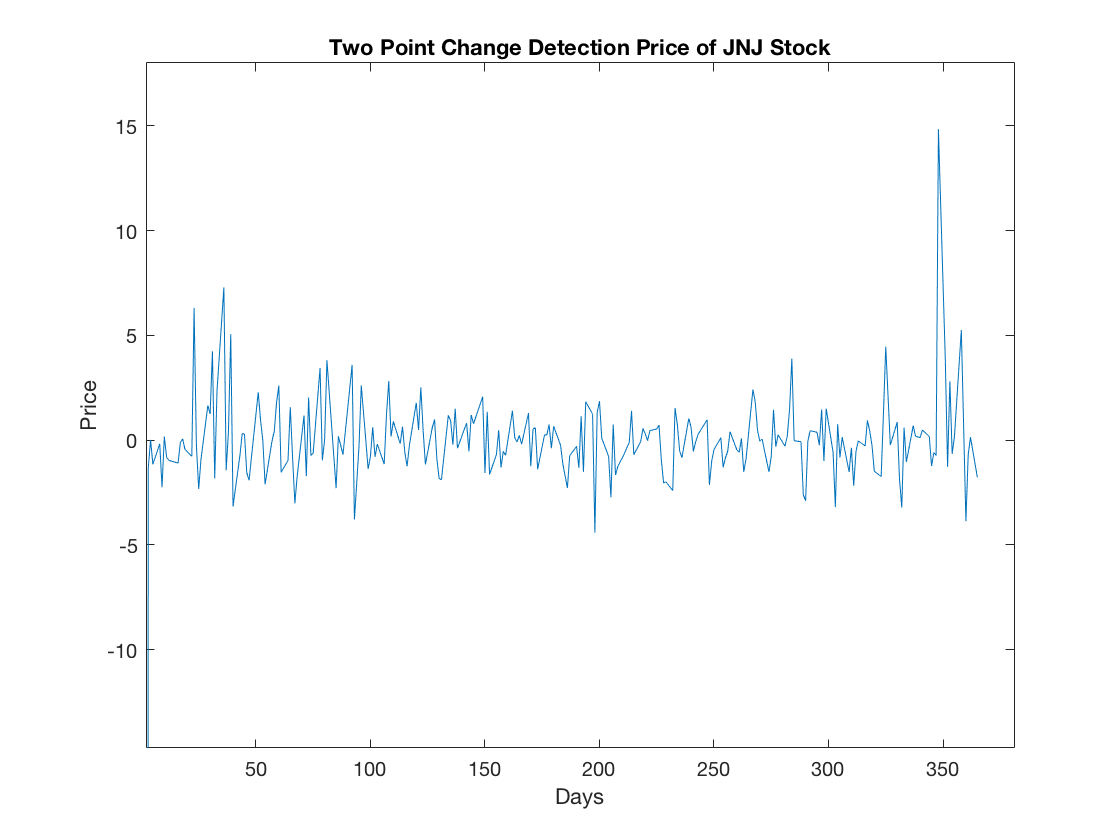

jnj_high_passed = filter(two_point_change_detection, 1, jnj);
figure; plot(dayofyear, jnj_high_passed);
xlabel('Days'), ylabel('Price')
title('Two Point Change Detection Price of JNJ Stock')
xlim([2 381]);ylim([-14.7 18.0]);

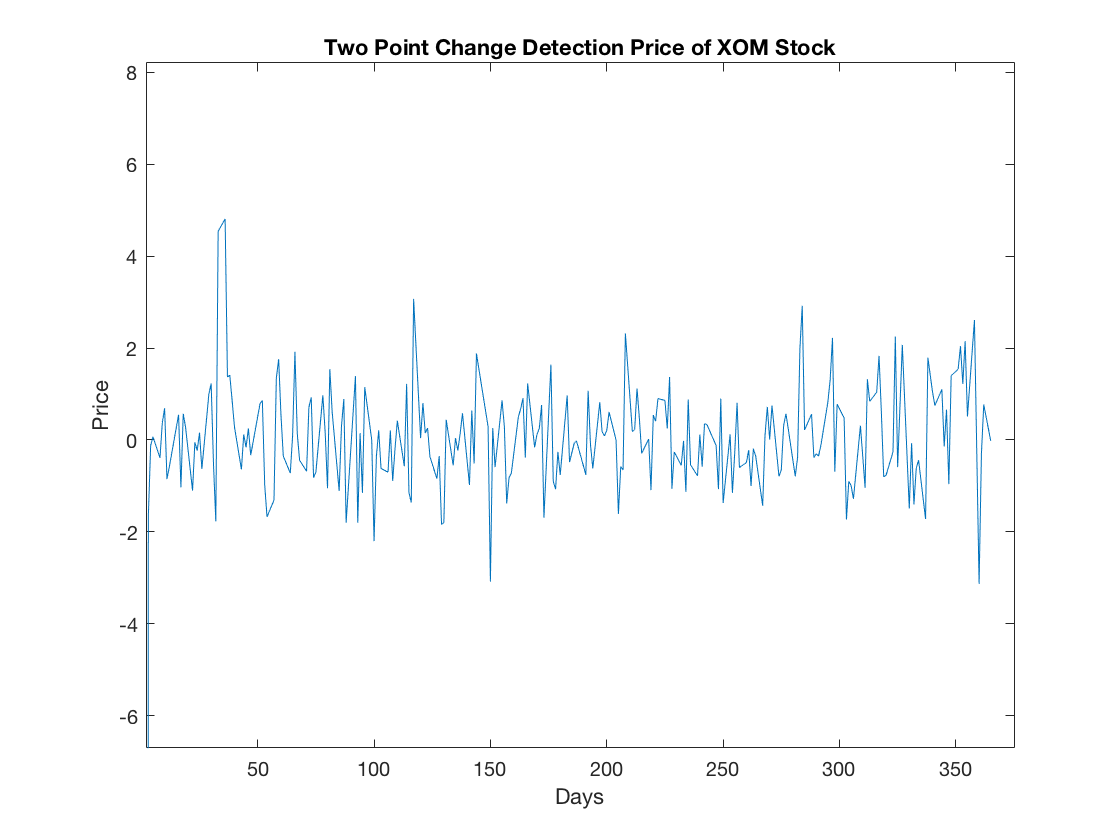

xom_high_passed = filter(two_point_change_detection, 1, xom);
figure; plot(dayofyear, xom_high_passed);
xlabel('Days'), ylabel('Price')
title('Two Point Change Detection Price of XOM Stock')
xlim([2 375]);ylim([-6.7 8.2]);

** B) **Apply 3 point change detection filter to the 3 stock sequences illustrated in part 1.

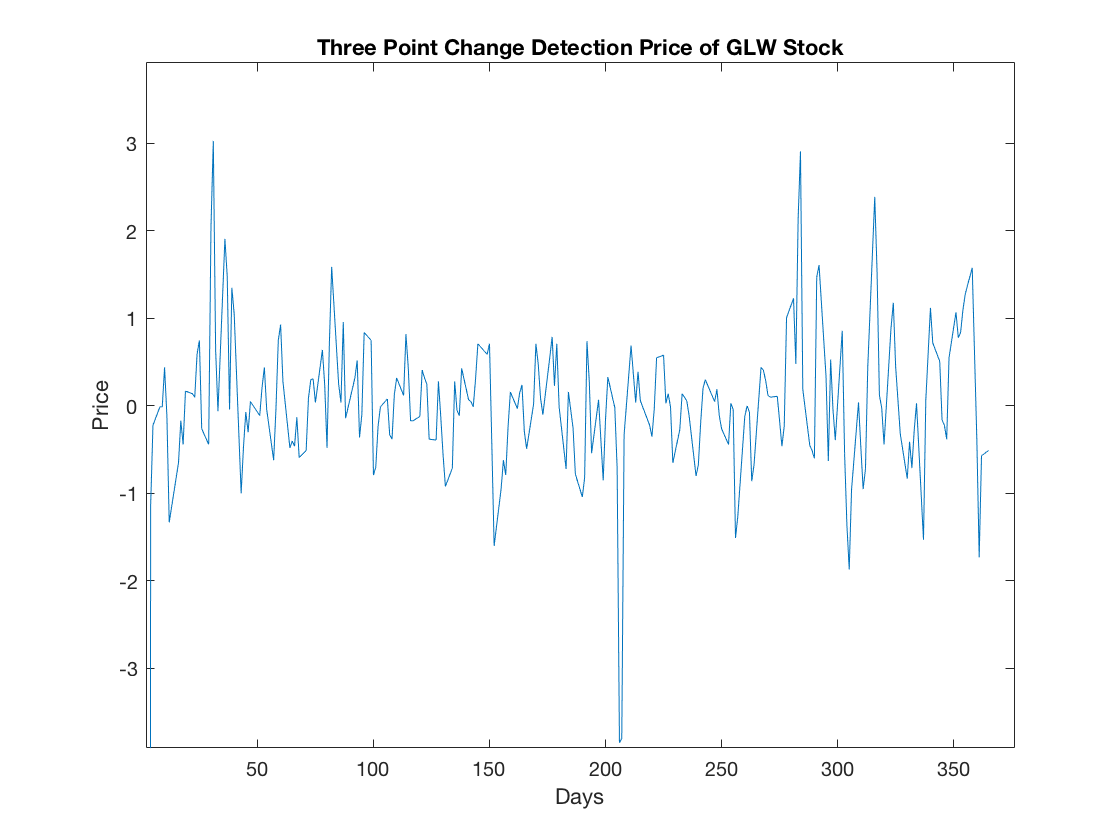

three_point_change_detection = [-1, 0, 1];
glw_high_passed = filter(three_point_change_detection, 1, glw);
figure; plot(dayofyear, glw_high_passed);
xlabel('Days'), ylabel('Price')
title('Three Point Change Detection Price of GLW Stock')
xlim([2 376]);ylim([-3.91 3.92]);

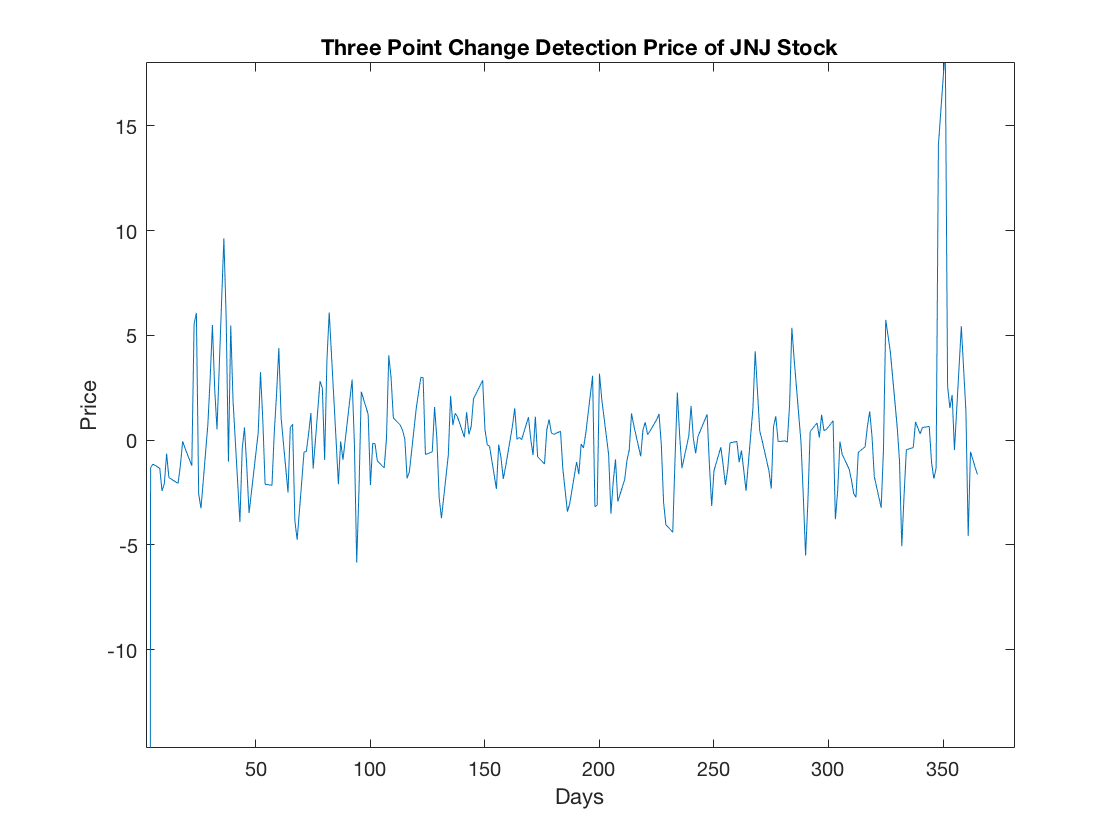

jnj_high_passed = filter(three_point_change_detection, 1, jnj);
figure; plot(dayofyear, jnj_high_passed);
xlabel('Days'), ylabel('Price')
title('Three Point Change Detection Price of JNJ Stock')
xlim([2 381]);ylim([-14.7 18.0]);

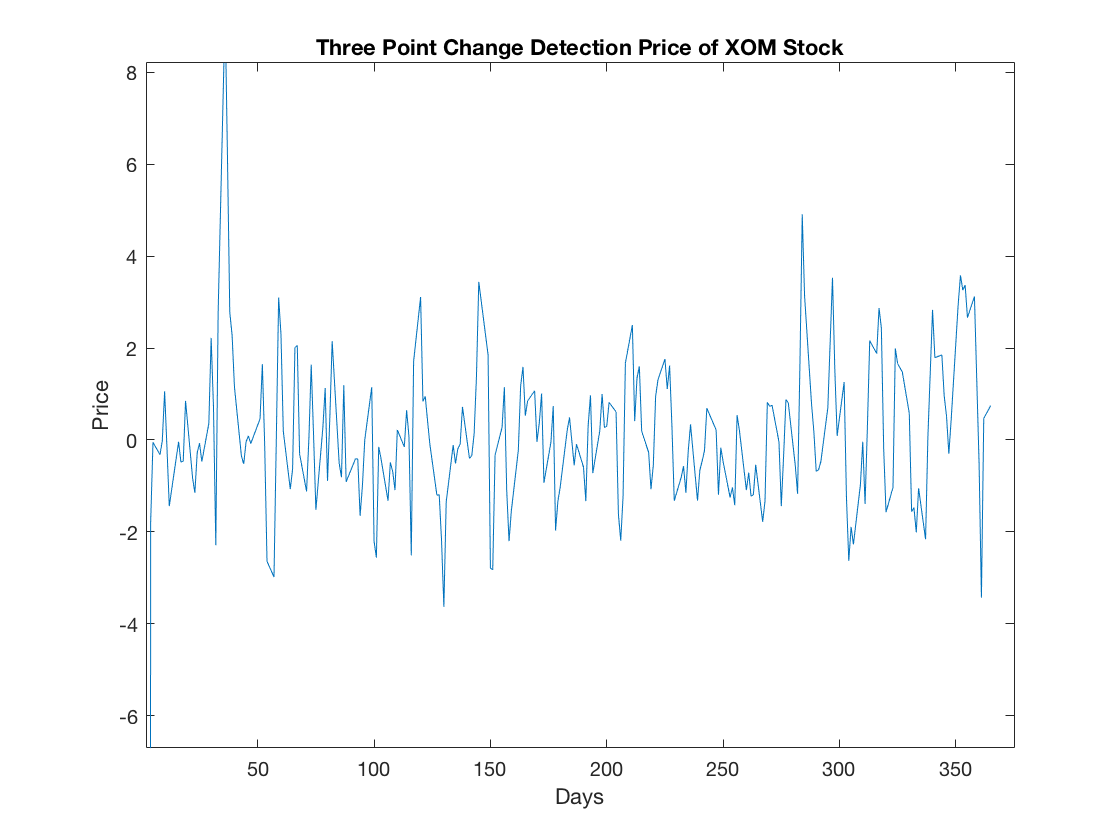

xom_high_passed = filter(three_point_change_detection, 1, xom);
figure; plot(dayofyear, xom_high_passed);
xlabel('Days'), ylabel('Price')
title('Three Point Change Detection Price of XOM Stock')
xlim([2 375]);ylim([-6.7 8.2]);

** C) **Apply 5 point change detection filter to the 3 stock sequences illustrated in part 1.

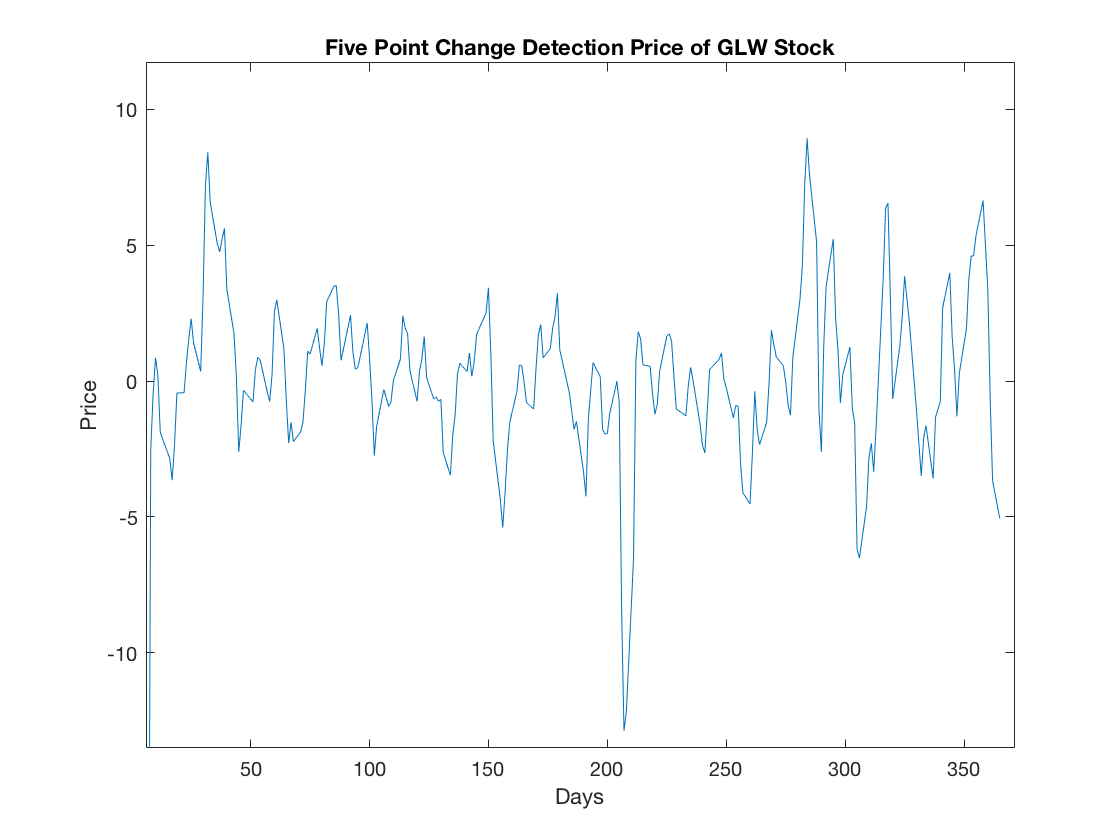

five_point_change_detection = [-2,-1,0, 1,2];
glw_high_passed = filter(five_point_change_detection, 1, glw);
figure; plot(dayofyear, glw_high_passed);
xlabel('Days'), ylabel('Price')
title('Five Point Change Detection Price of GLW Stock')
xlim([6 371]); ylim([-13.5 11.7]);

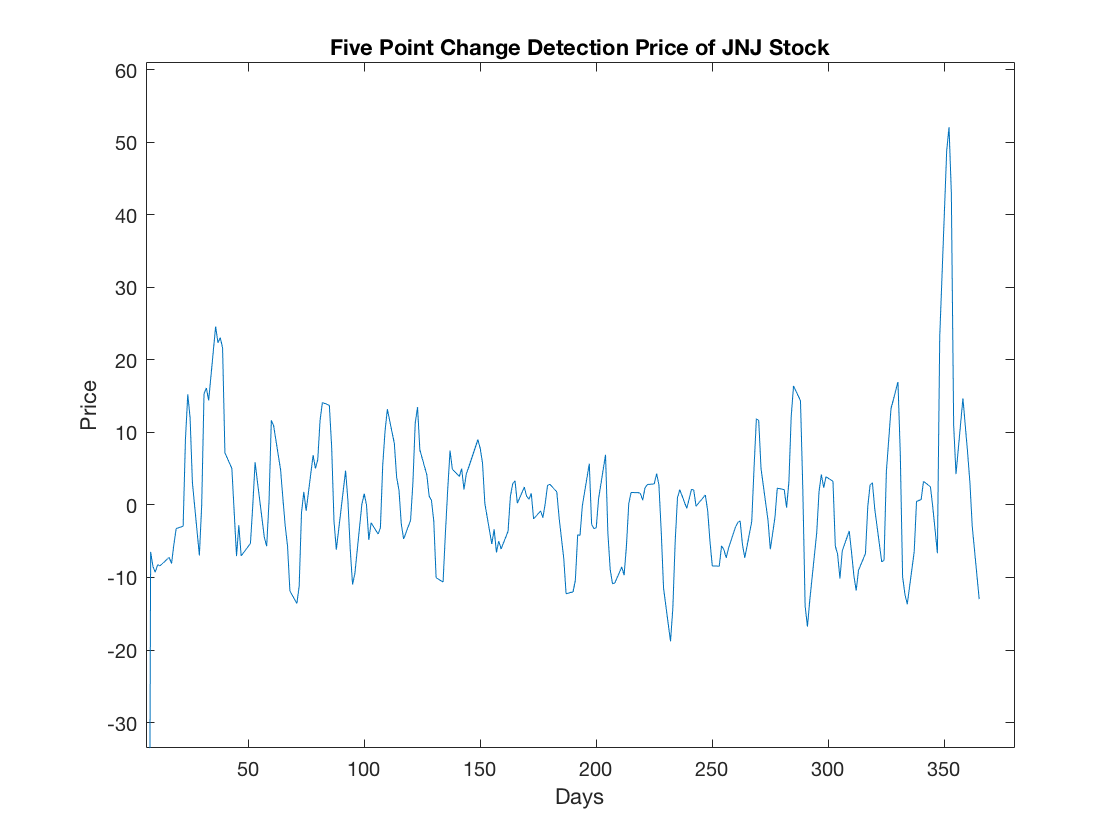

jnj_high_passed = filter(five_point_change_detection, 1, jnj);
figure; plot(dayofyear, jnj_high_passed);
xlabel('Days'), ylabel('Price')
title('Five Point Change Detection Price of JNJ Stock')
xlim([6 380]); ylim([-33.5 60.9]);

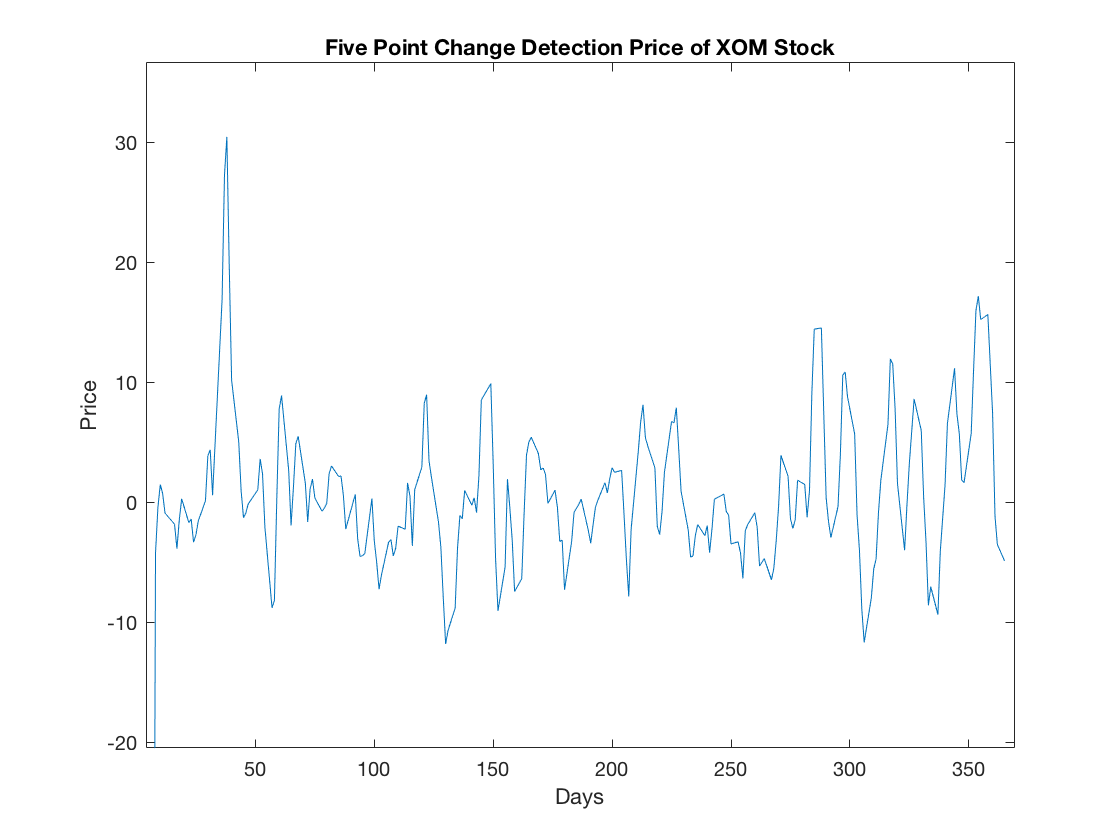

xom_high_passed = filter(five_point_change_detection, 1, xom);
figure; plot(dayofyear, xom_high_passed);
xlabel('Days'), ylabel('Price')
title('Five Point Change Detection Price of XOM Stock')
xlim([4 369]); ylim([-20.5 36.6]);

**D) **Observe Frequency Spectra of all three high passed sequences. I am choosing to run FFT on the five point change detection sequences. Interesting enough, running FFT with the three modes (2 point, 3 point, and 5 point) resulted in pretty different plots. The 2 point change detection filter resulted in the best high pass filter, significantly attenuating the lowering frequencies in comparison to the 5 point detection filter.

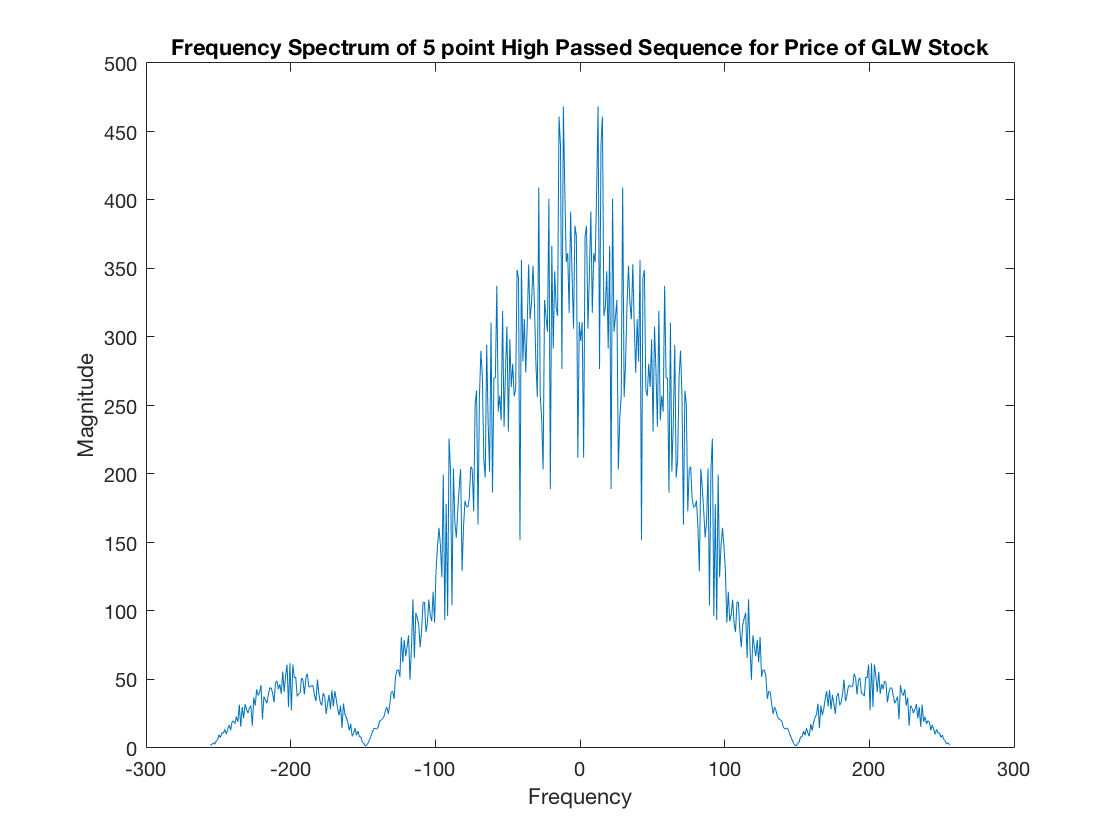

fft_glw = abs(fftshift(fft(glw_high_passed, 512)));
fft_jnj = abs(fftshift(fft(jnj_high_passed, 512)));
fft_xom = abs(fftshift(fft(xom_high_passed, 512)));
f = -511/2:511/2;

figure; plot(f,fft_glw);
xlabel('Frequency'), ylabel('Magnitude')
title('Frequency Spectrum of 5 point High Passed Sequence for Price of GLW Stock')

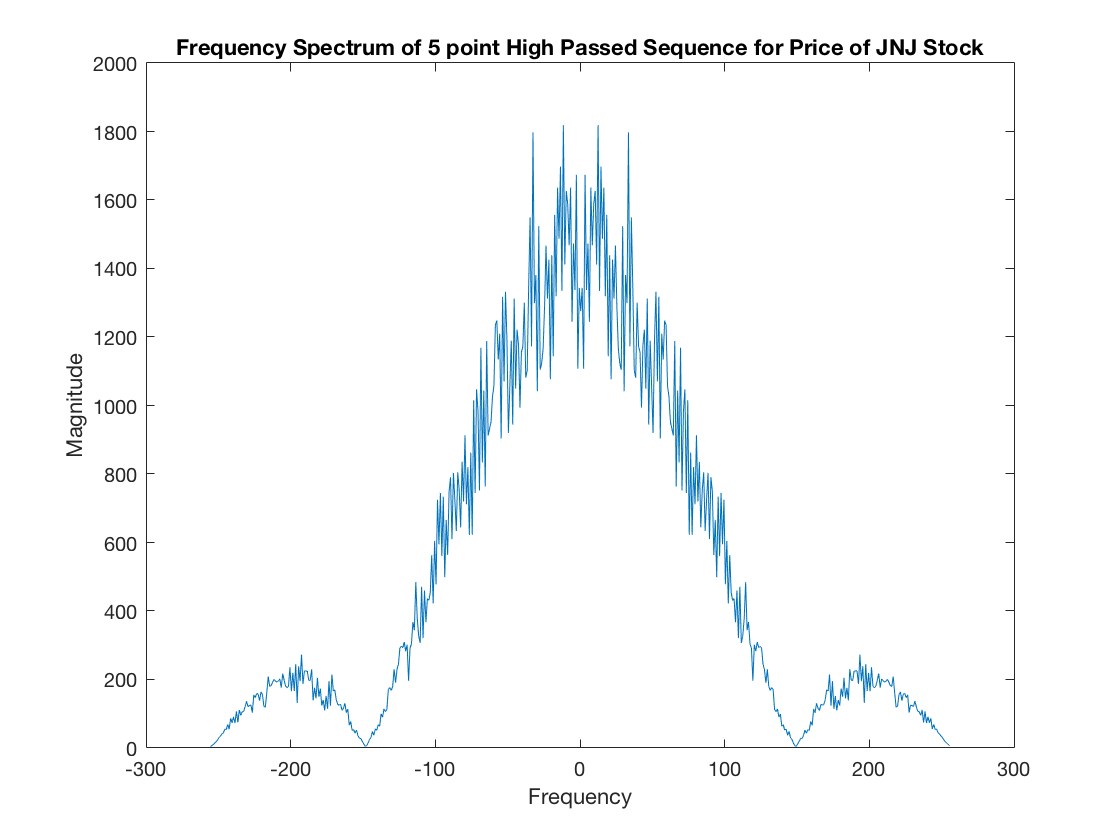

figure; plot(f,fft_jnj);
xlabel('Frequency'), ylabel('Magnitude')
title('Frequency Spectrum of 5 point High Passed Sequence for Price of JNJ Stock')

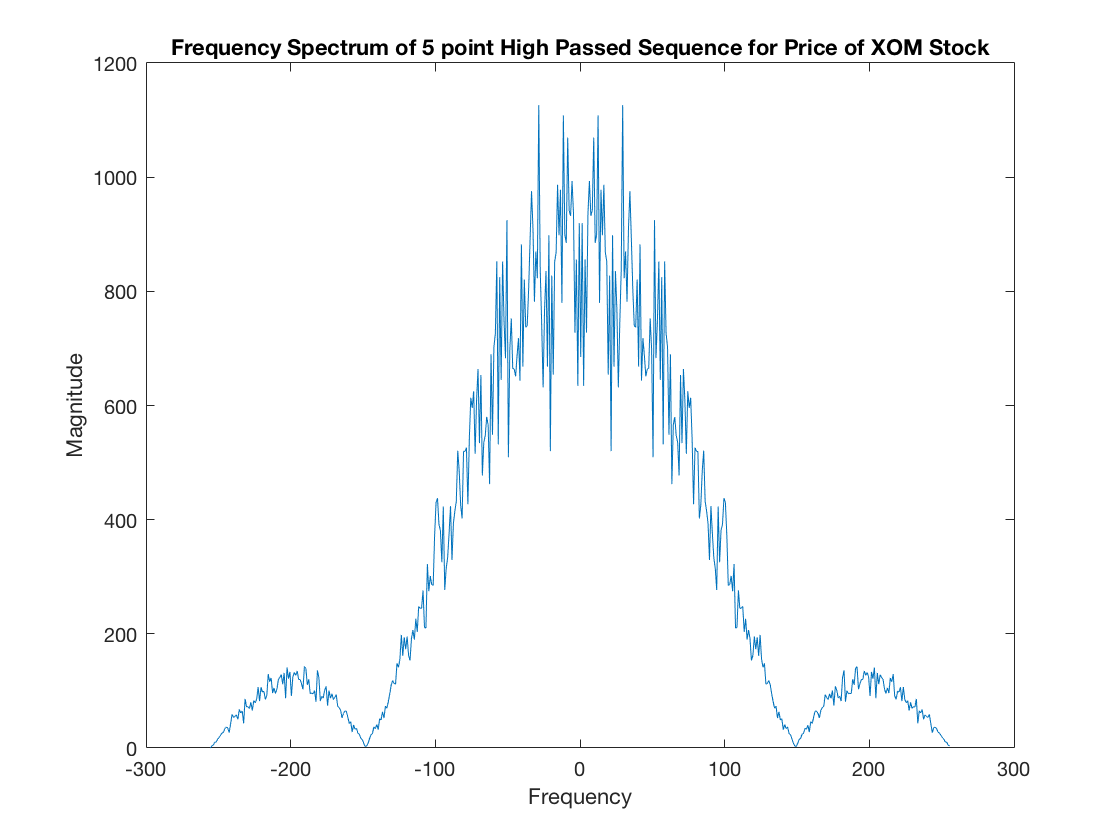

figure; plot(f,fft_xom);
xlabel('Frequency'), ylabel('Magnitude')
title('Frequency Spectrum of 5 point High Passed Sequence for Price of XOM Stock')

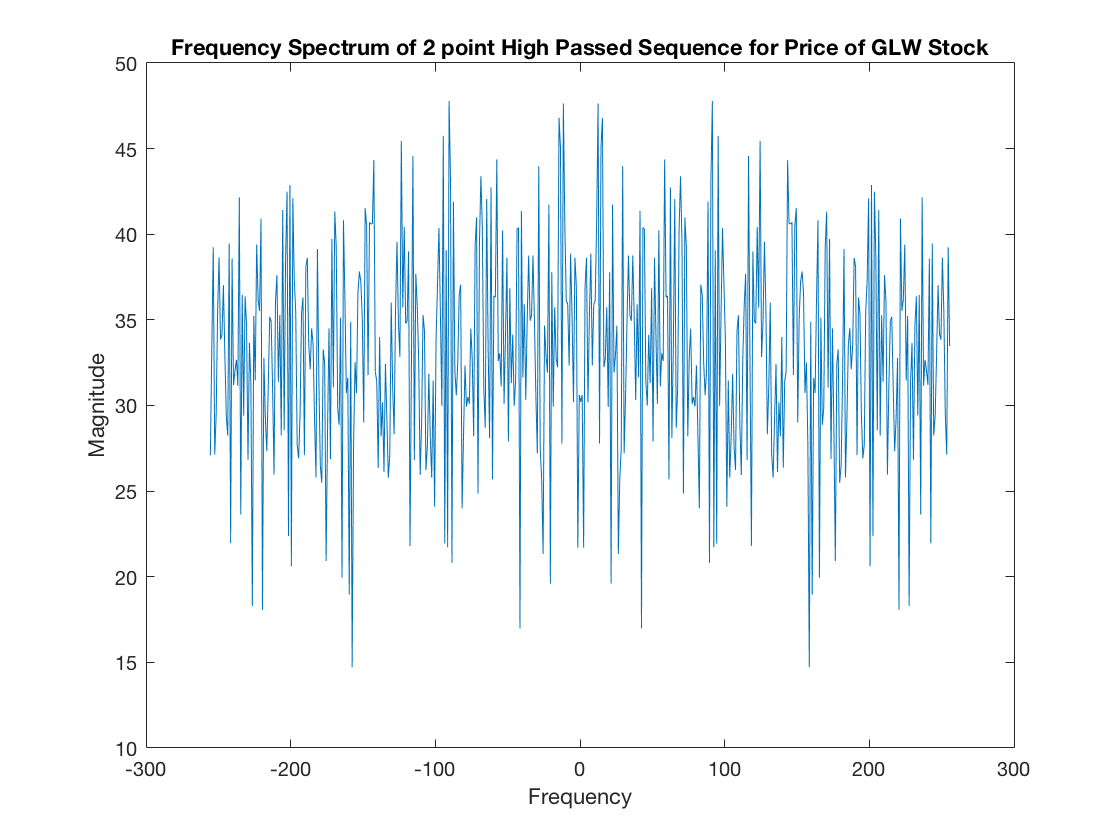


two_point_change_detection = [-1,1];
glw_high_passed = filter(two_point_change_detection, 1, glw);
jnj_high_passed = filter(two_point_change_detection, 1, jnj);
xom_high_passed = filter(two_point_change_detection, 1, xom);

fft_glw = abs(fftshift(fft(glw_high_passed, 512)));
fft_jnj = abs(fftshift(fft(jnj_high_passed, 512)));
fft_xom = abs(fftshift(fft(xom_high_passed, 512)));
f = -511/2:511/2;

figure; plot(f,fft_glw);
xlabel('Frequency'), ylabel('Magnitude')
title('Frequency Spectrum of 2 point High Passed Sequence for Price of GLW Stock')

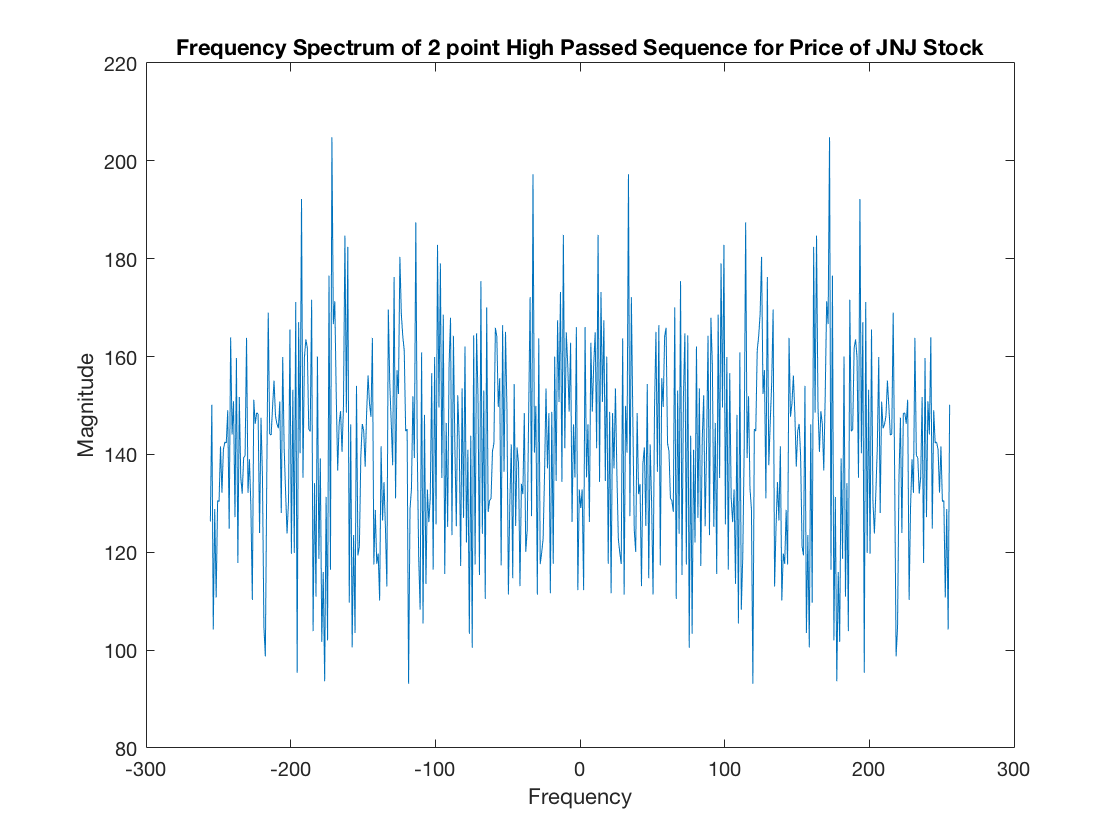

figure; plot(f,fft_jnj);
xlabel('Frequency'), ylabel('Magnitude')
title('Frequency Spectrum of 2 point High Passed Sequence for Price of JNJ Stock')

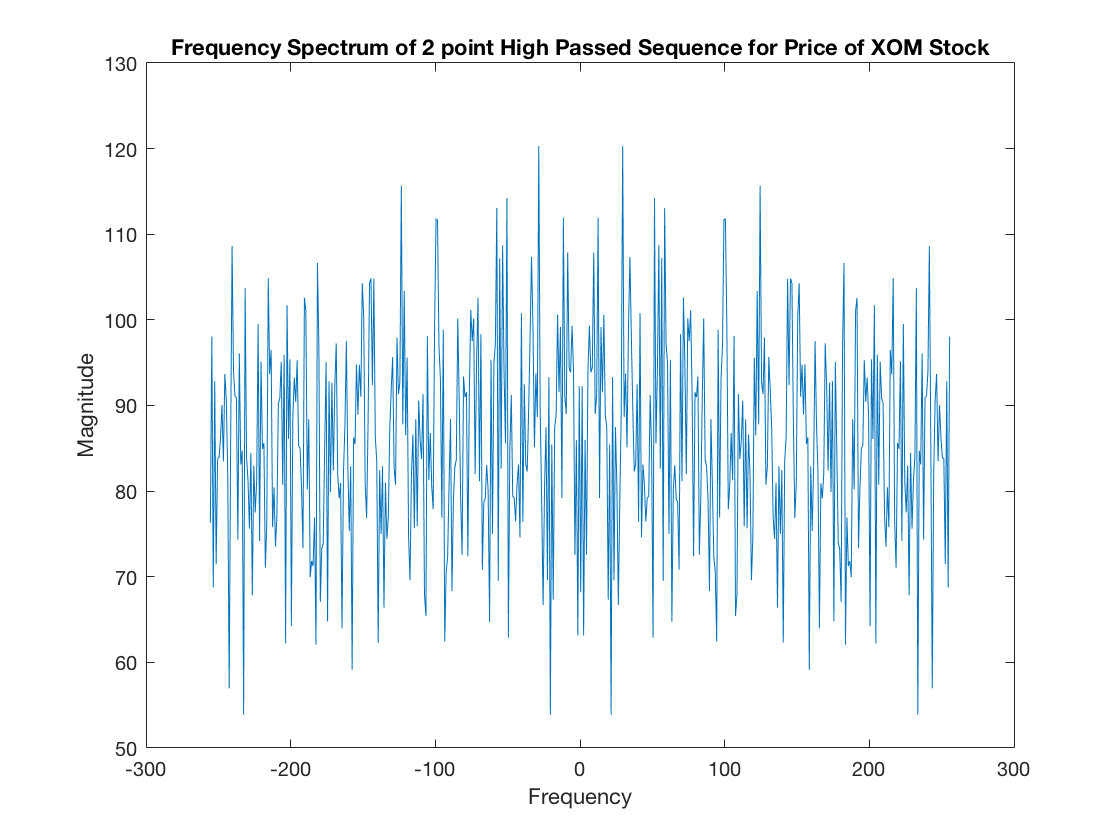

figure; plot(f,fft_xom);
xlabel('Frequency'), ylabel('Magnitude')
title('Frequency Spectrum of 2 point High Passed Sequence for Price of XOM Stock')

**F) **Based on my high passed plots, I can conclude that the peaks correspond to significant changes in the stock price. For GLW, days 31, 206, and 284 correspond to a peak in the high pass plots, meaning that these dates were a good day to either buy or sell stock. JNJ also had a signifacnt peak in it' s high pass plot, day 351 had the biggest peak of the year and signifies a great day to sell stock. Finally, XOM exhibits significant spikes at days 36 and 284, great dates to sell XOM stock. These dates agree with the dates found previously from the Bollinger Band plots.

## Part 4: Peak Detection (**highpass filtering, 2nd-order)**

**A) **Apply the 3 point peak detection filter to the 3 sequences.

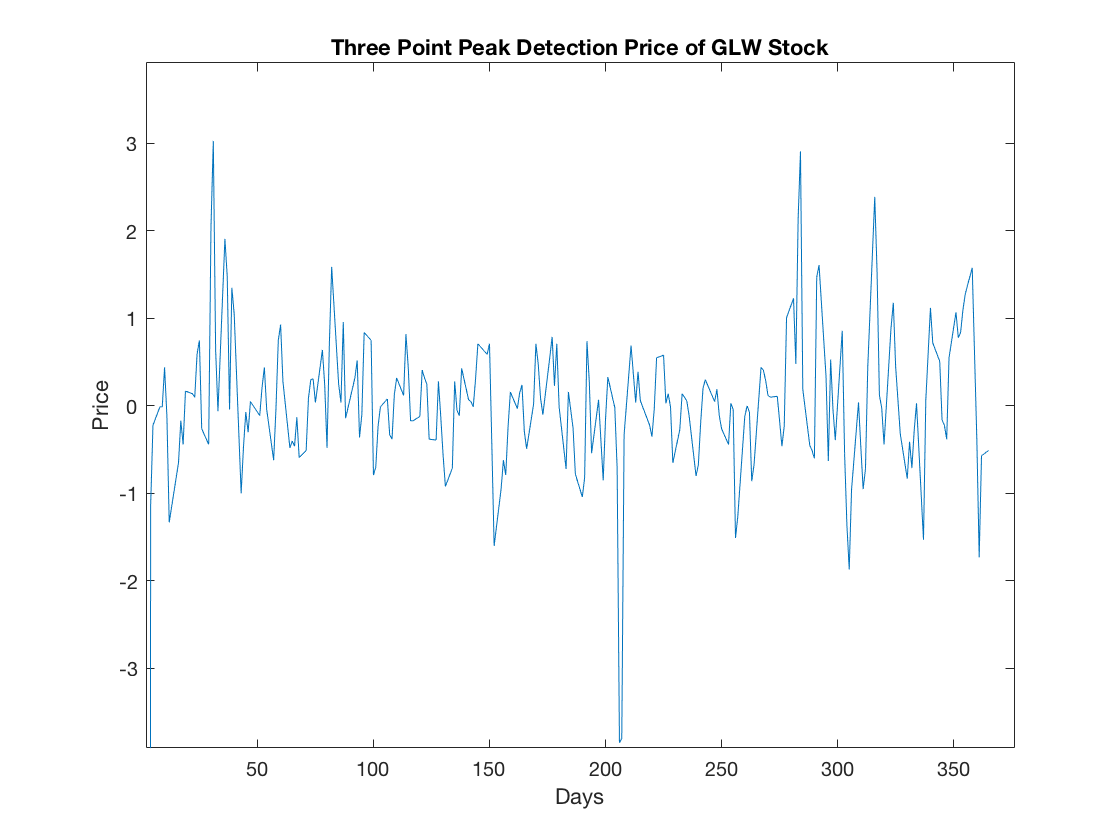

three_point_peak_detection = [-1/2, 1, -1/2];
glw_high_passed = filter(three_point_change_detection, 1, glw);
figure; plot(dayofyear, glw_high_passed);
xlabel('Days'), ylabel('Price')
title('Three Point Peak Detection Price of GLW Stock')
xlim([2 376]);ylim([-3.91 3.92]);

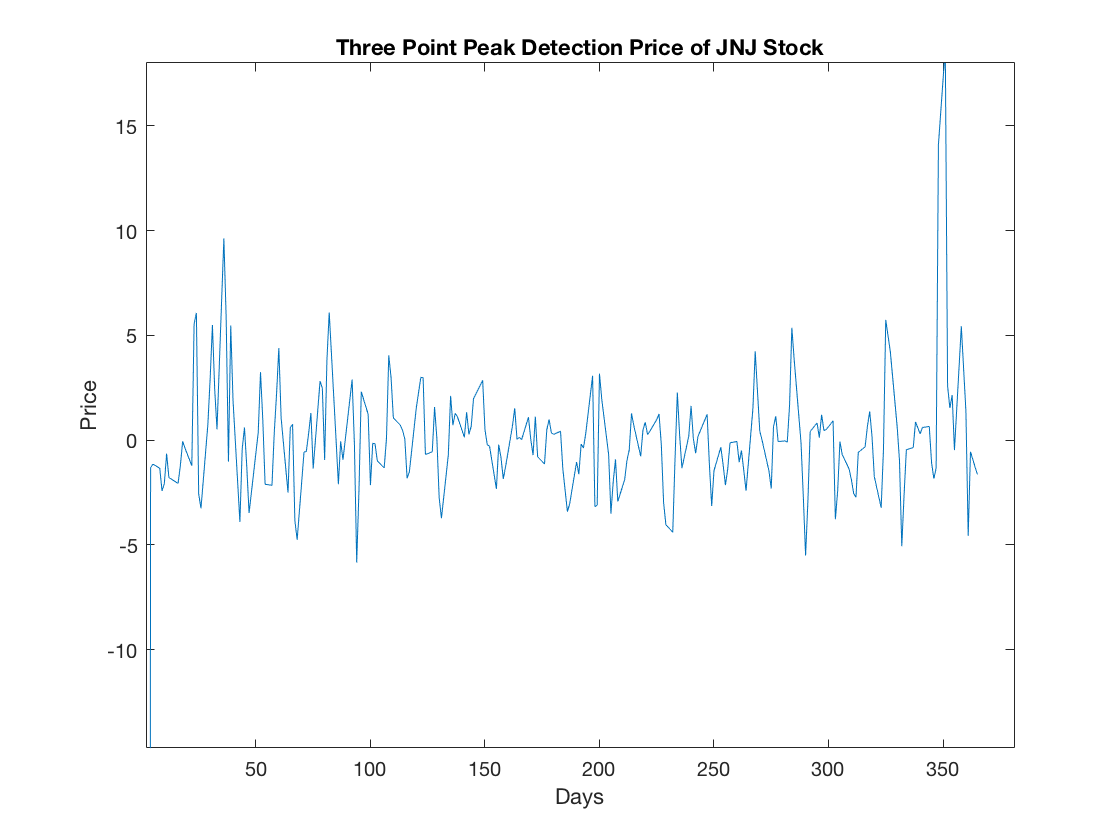

jnj_high_passed = filter(three_point_change_detection, 1, jnj);
figure; plot(dayofyear, jnj_high_passed);
xlabel('Days'), ylabel('Price')
title('Three Point Peak Detection Price of JNJ Stock')
xlim([2 381]);ylim([-14.7 18.0]);

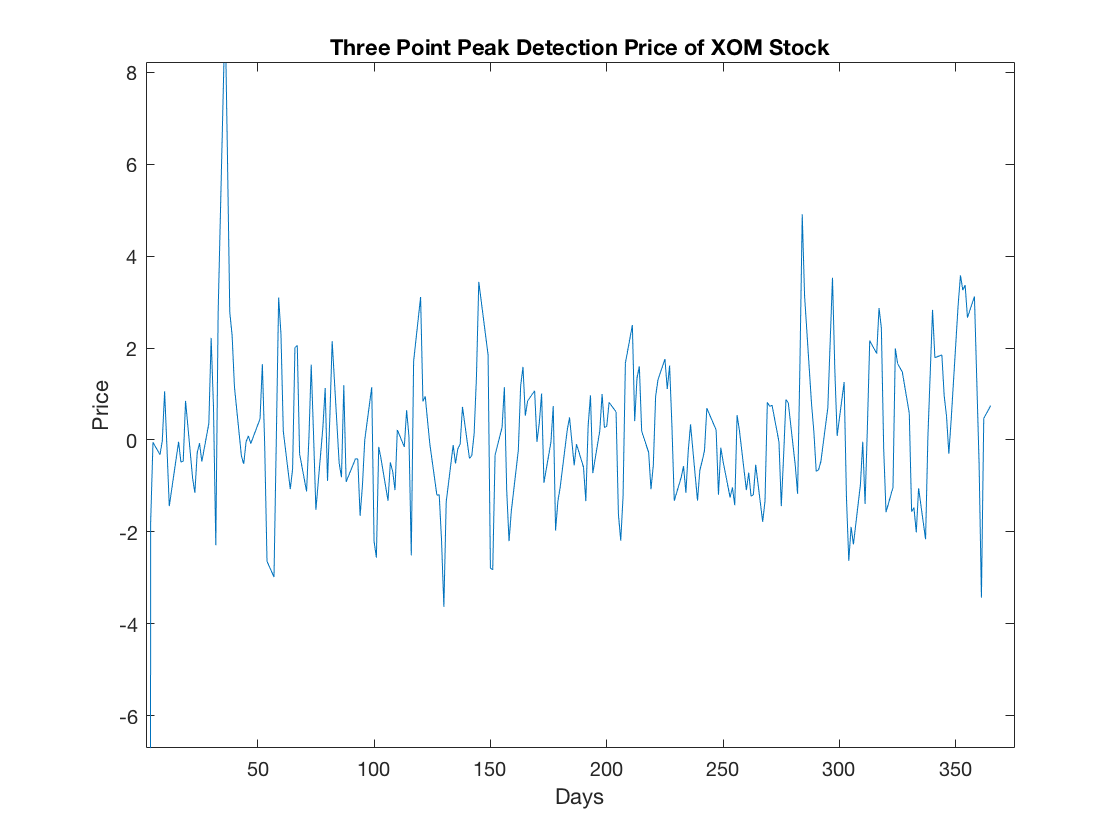

xom_high_passed = filter(three_point_change_detection, 1, xom);
figure; plot(dayofyear, xom_high_passed);
xlabel('Days'), ylabel('Price')
title('Three Point Peak Detection Price of XOM Stock')
xlim([2 375]);ylim([-6.7 8.2]);

**B) **Apply the 5 point peak detection filter to the 3 sequences.

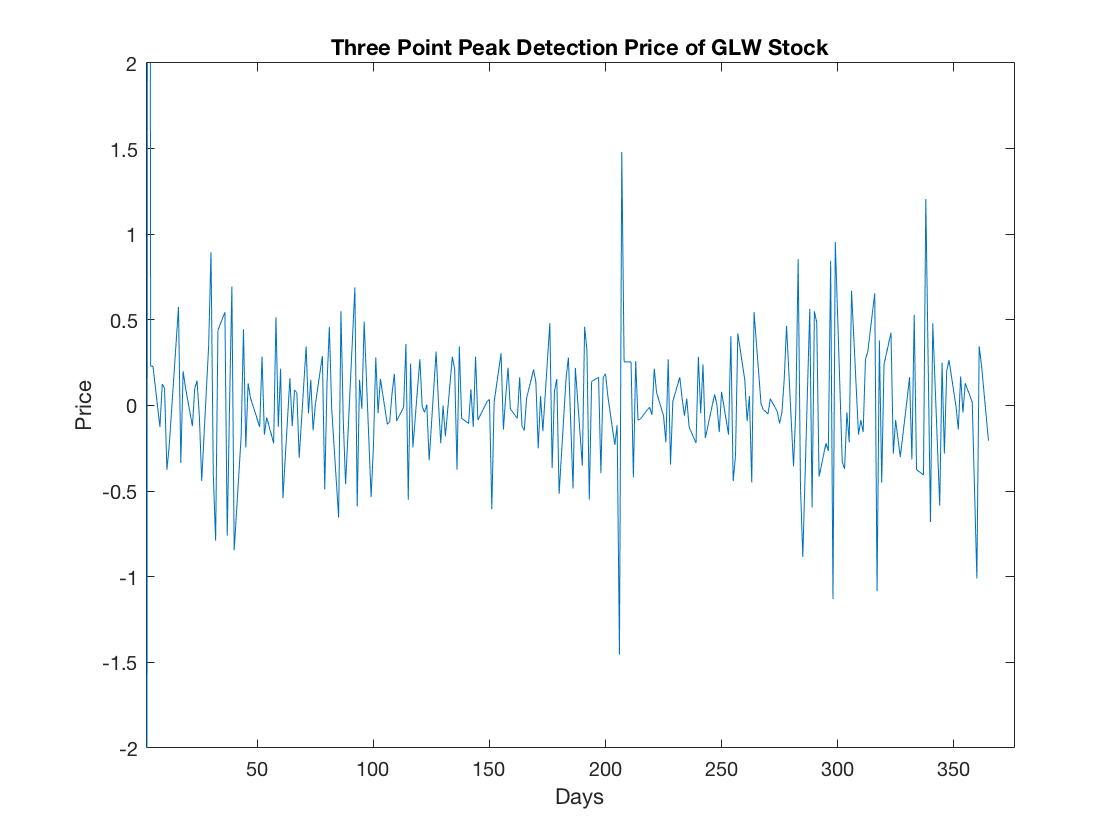

five_point_peak_detection = [-1/2, 1, -1/2];
glw_high_passed = filter(five_point_peak_detection, 1, glw);
figure; plot(dayofyear, glw_high_passed);
xlabel('Days'), ylabel('Price')
title('Three Point Peak Detection Price of GLW Stock')
xlim([2 376]);ylim([-2 2]);

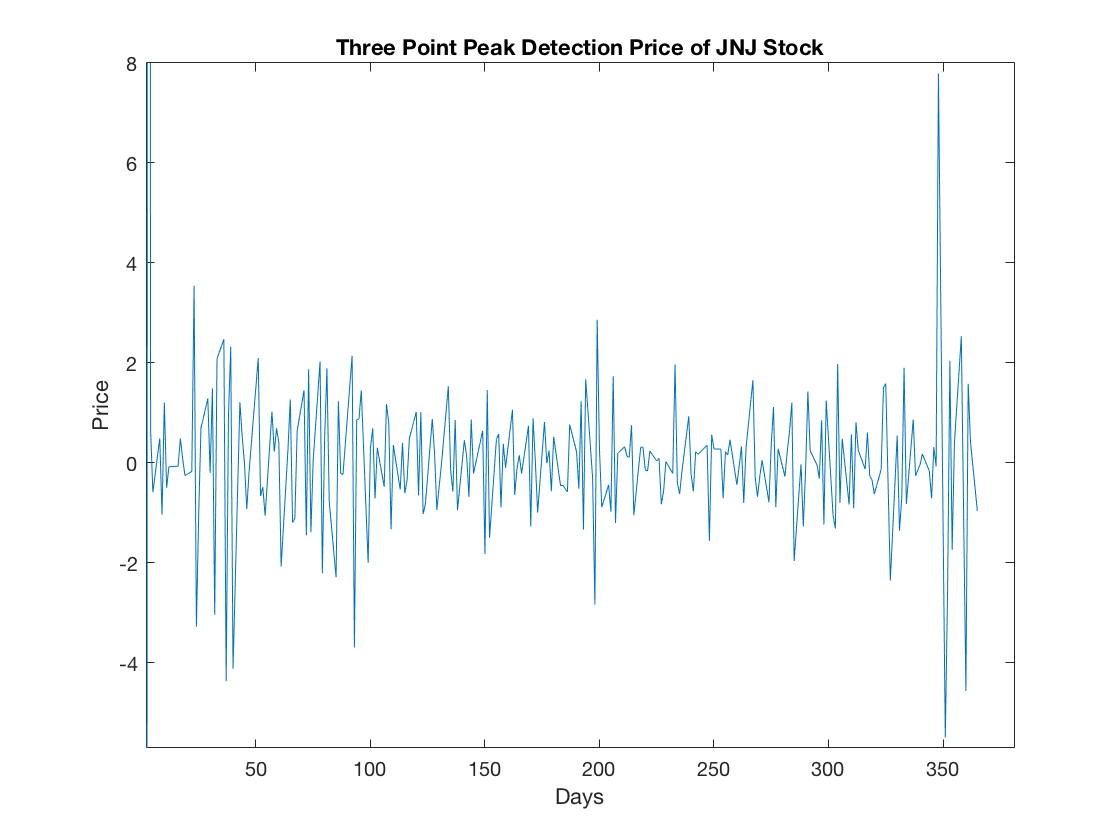

jnj_high_passed = filter(five_point_peak_detection, 1, jnj);
figure; plot(dayofyear, jnj_high_passed);
xlabel('Days'), ylabel('Price')
title('Three Point Peak Detection Price of JNJ Stock')
xlim([2 381]);ylim([-5.7 8.0]);

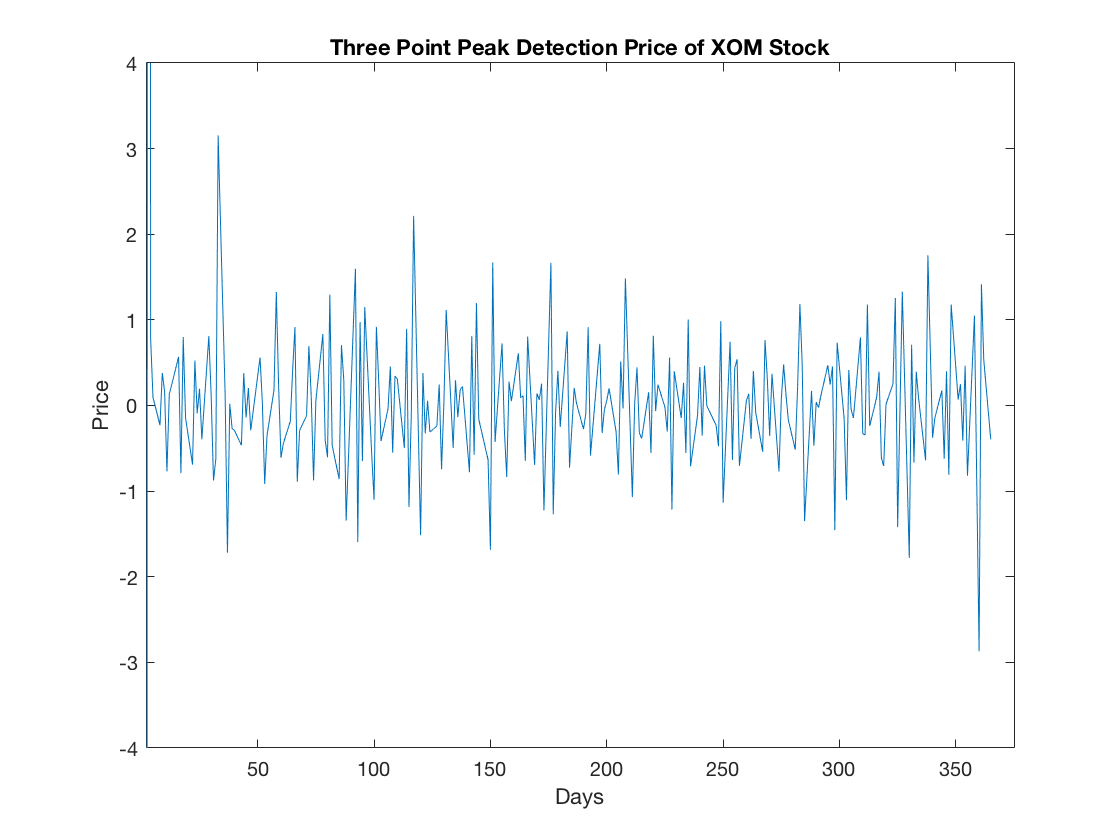

xom_high_passed = filter(five_point_peak_detection, 1, xom);
figure; plot(dayofyear, xom_high_passed);
xlabel('Days'), ylabel('Price')
title('Three Point Peak Detection Price of XOM Stock')
xlim([2 375]);ylim([-4 4]);

**C) **Observe the frequency spectra of both high passed sequences.

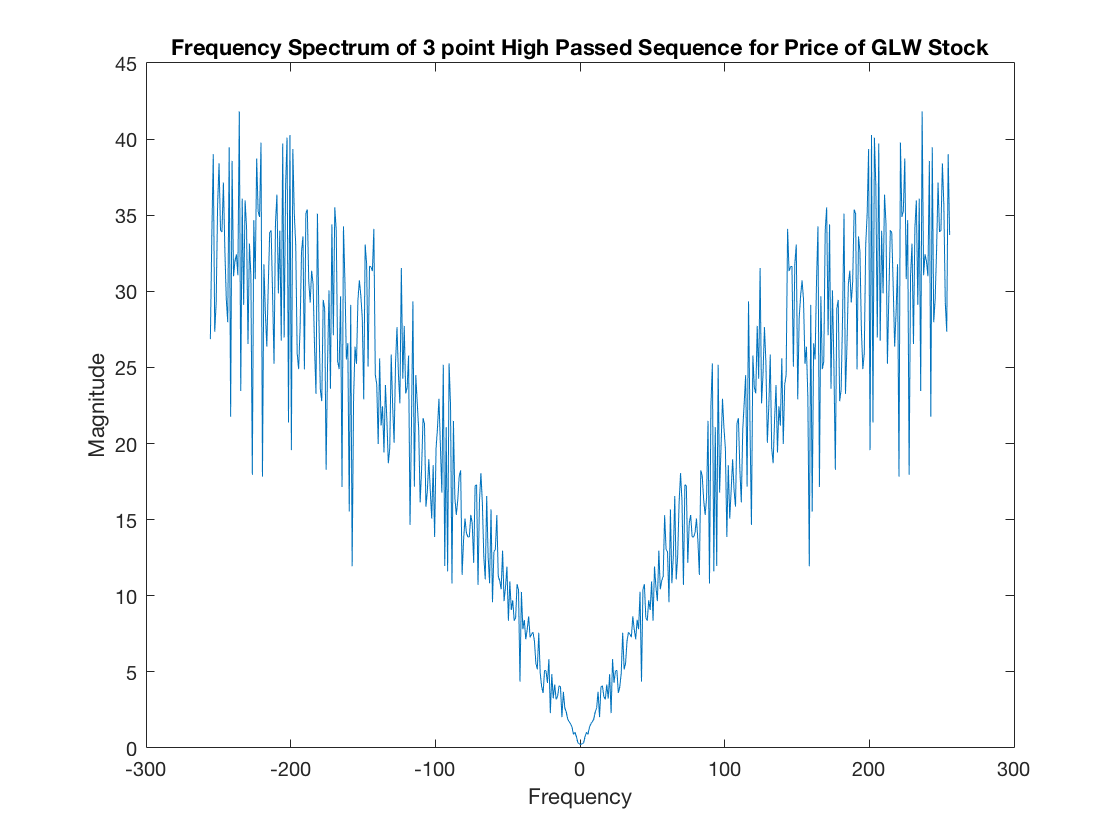

fft_glw = abs(fftshift(fft(glw_high_passed, 512)));
fft_jnj = abs(fftshift(fft(jnj_high_passed, 512)));
fft_xom = abs(fftshift(fft(xom_high_passed, 512)));
f = -511/2:511/2;
figure; plot(f,fft_glw);
xlabel('Frequency'), ylabel('Magnitude')
title('Frequency Spectrum of 3 point High Passed Sequence for Price of GLW Stock')

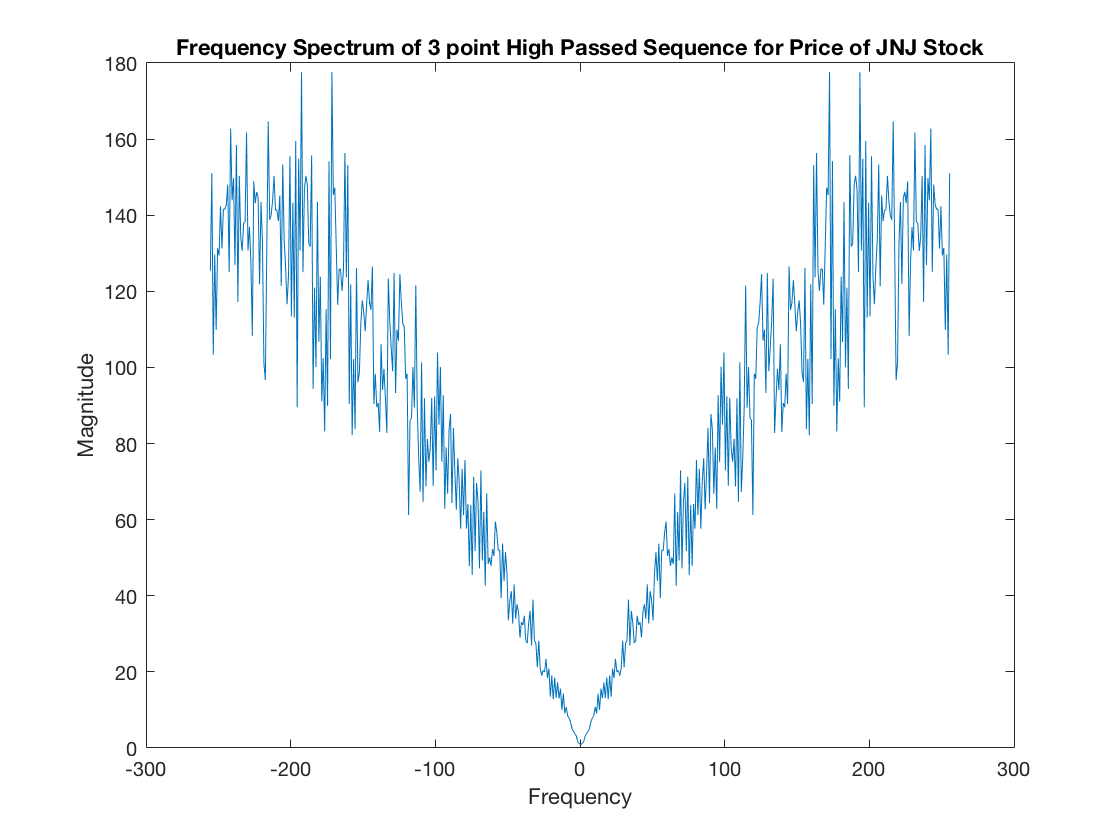

figure; plot(f,fft_jnj);
xlabel('Frequency'), ylabel('Magnitude')
title('Frequency Spectrum of 3 point High Passed Sequence for Price of JNJ Stock')

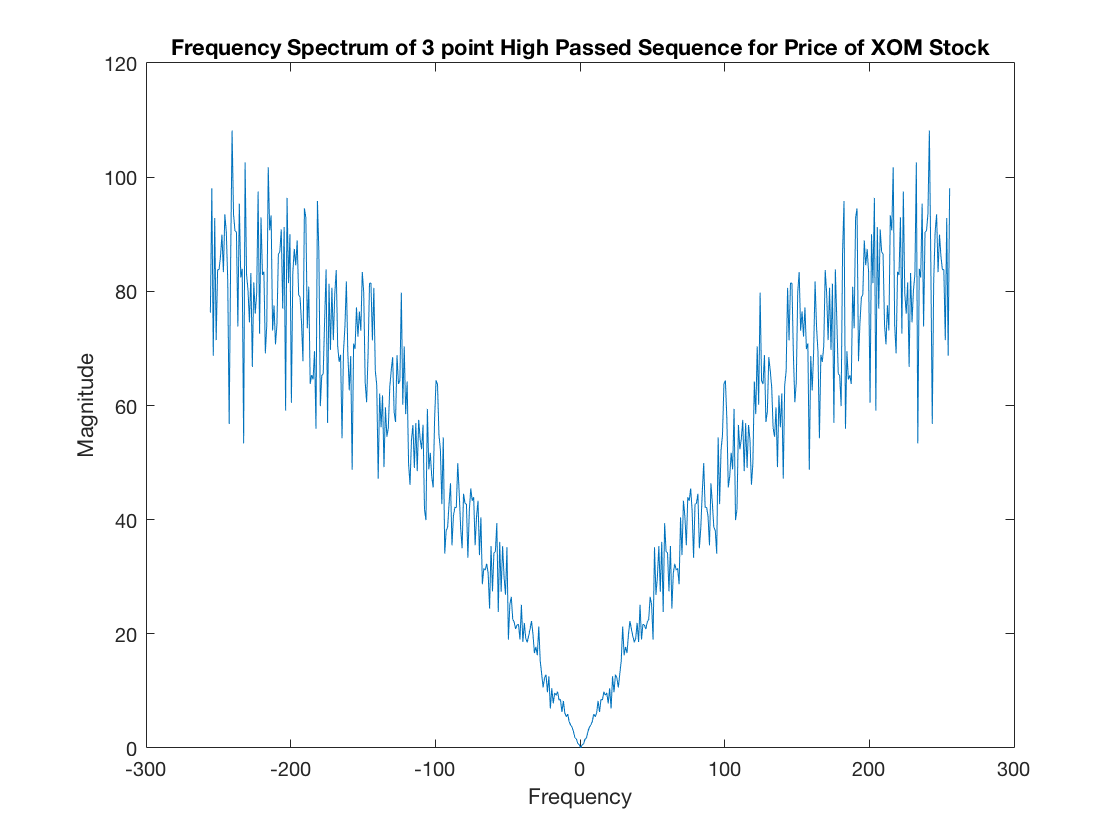

figure; plot(f,fft_xom);
xlabel('Frequency'), ylabel('Magnitude')
title('Frequency Spectrum of 3 point High Passed Sequence for Price of XOM Stock')

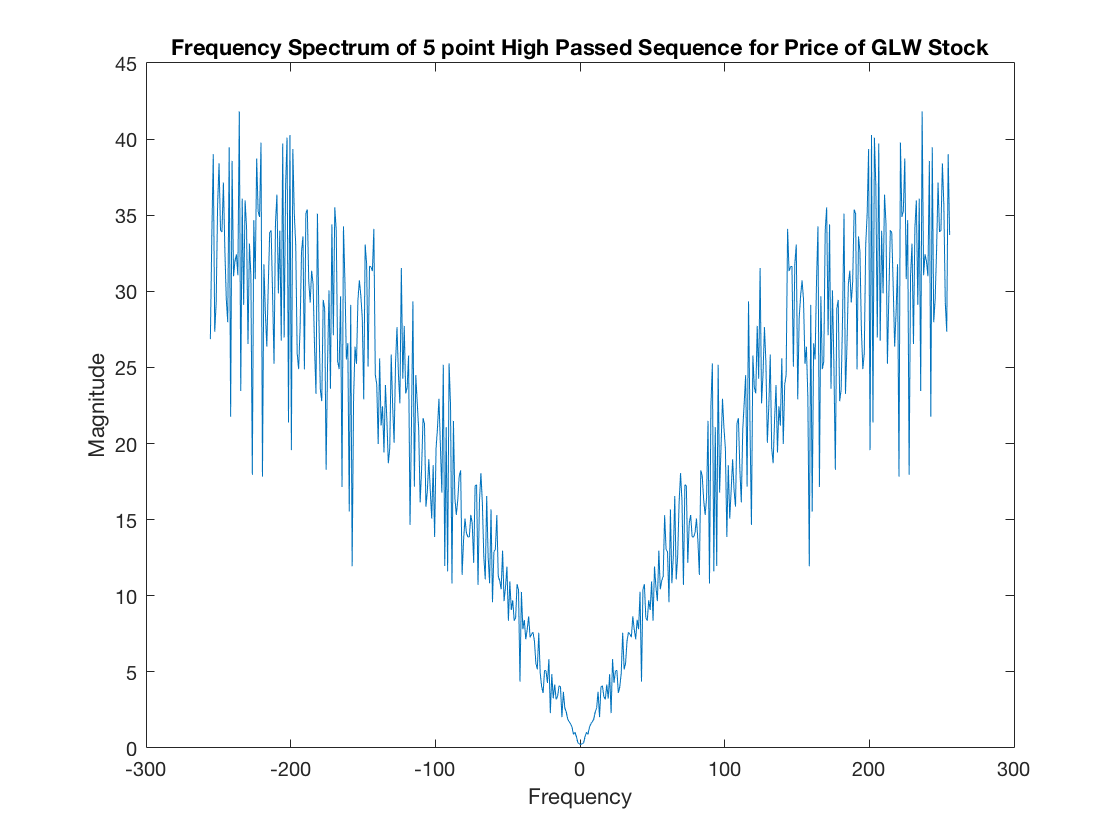


glw_high_passed = filter(five_point_peak_detection, 1, glw);
jnj_high_passed = filter(five_point_peak_detection, 1, jnj);
xom_high_passed = filter(five_point_peak_detection, 1, xom);

fft_glw = abs(fftshift(fft(glw_high_passed, 512)));
fft_jnj = abs(fftshift(fft(jnj_high_passed, 512)));
fft_xom = abs(fftshift(fft(xom_high_passed, 512)));


figure; plot(f,fft_glw);
xlabel('Frequency'), ylabel('Magnitude')
title('Frequency Spectrum of 5 point High Passed Sequence for Price of GLW Stock')

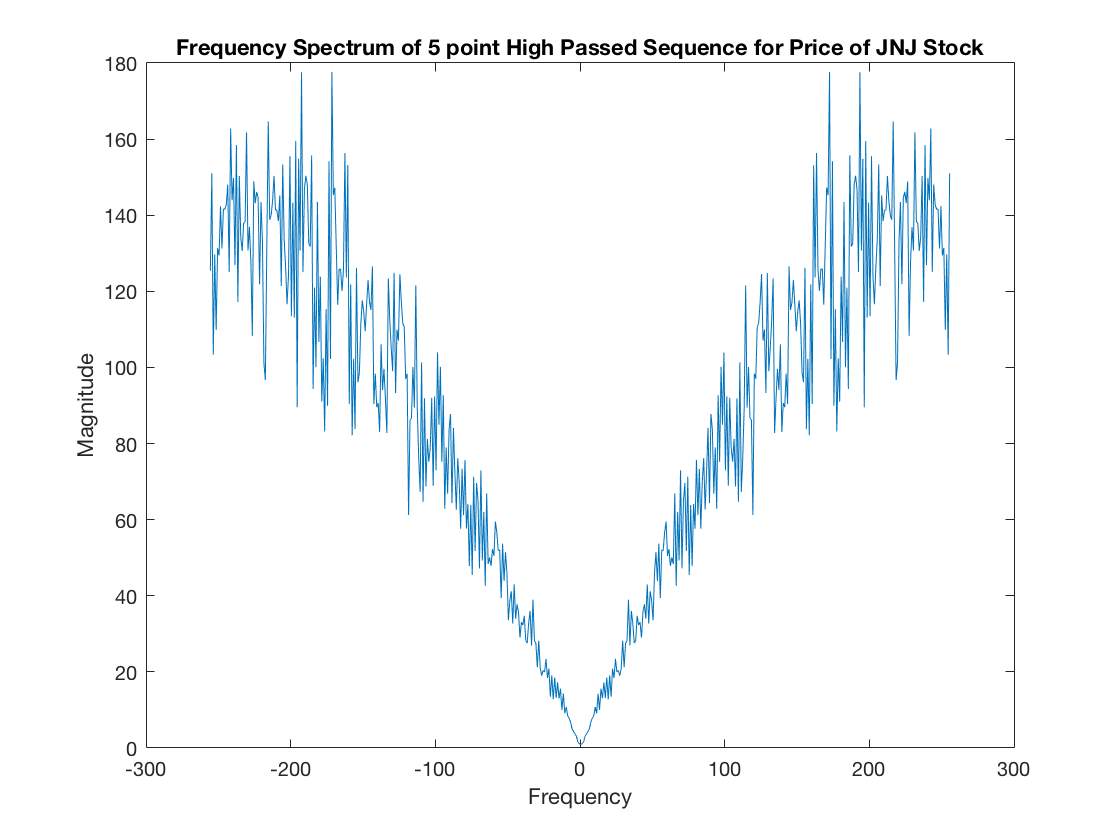

figure; plot(f,fft_jnj);
xlabel('Frequency'), ylabel('Magnitude')
title('Frequency Spectrum of 5 point High Passed Sequence for Price of JNJ Stock')

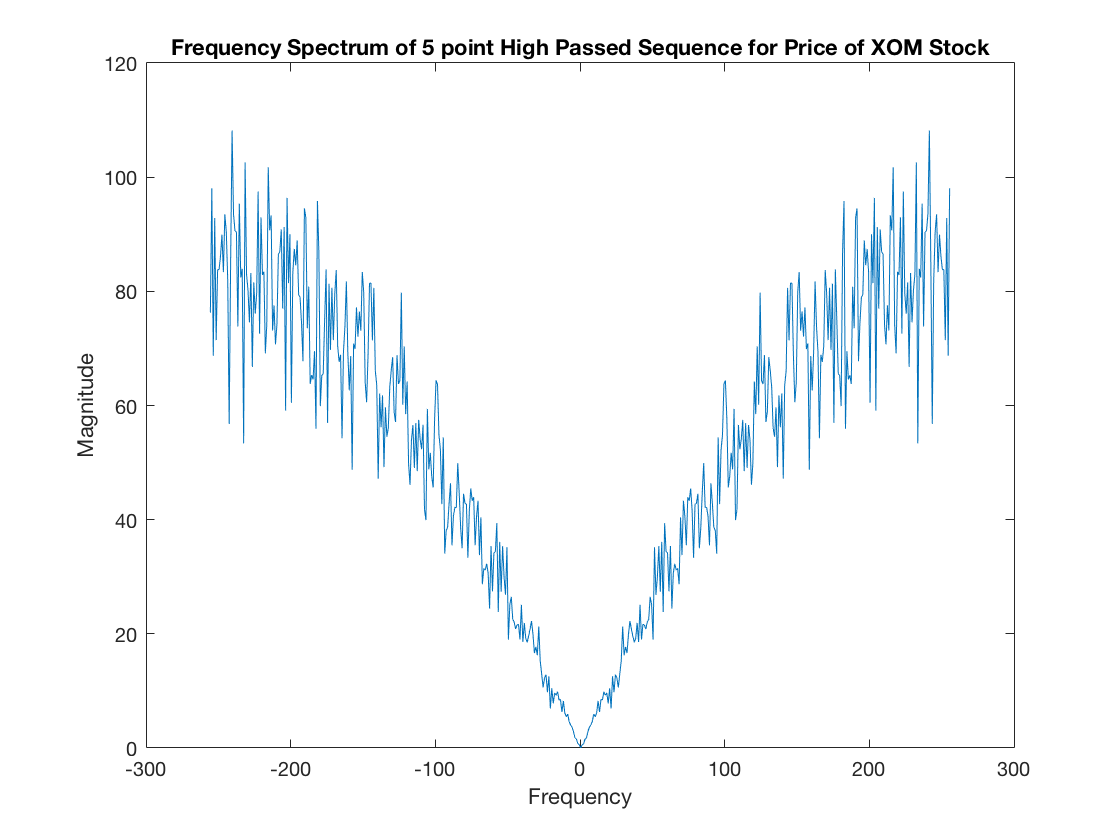

figure; plot(f,fft_xom);
xlabel('Frequency'), ylabel('Magnitude')
title('Frequency Spectrum of 5 point High Passed Sequence for Price of XOM Stock')

**D) **Much like Part 3, the plots of part 4 shows us significant peaks or spikes in the price of stock for each of the three companies. For GLW, days 31, 206, and 284 correspond to a peak in the high pass plots, meaning that these dates were a good day to either buy or sell stock. JNJ also had a signifacnt peak in it' s high pass plot, day 351 had the biggest peak of the year and signifies a great day to sell stock. Finally, XOM exhibits significant spikes at days 36 and 284, great dates to sell XOM stock. These dates agree with the dates found previously from the Bollinger Band plots and Part 3. Furthermore, the frequency spectra confirms that we have applied a peak detector filter to the original data as there mostly high frequencies present.